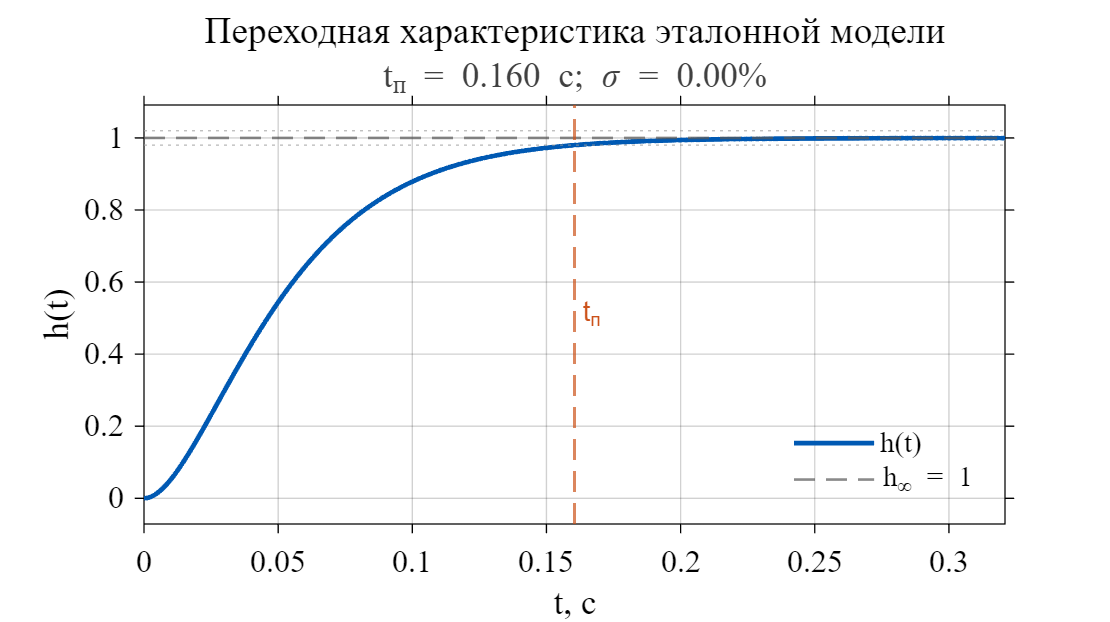

A_M = [0 1; -1329.9240 -72.9240];
B_M = [0; 1329.4782];
b_M = B_M;
out = sim('ystep');
y_st = out.y_step;
save(fullfile(fileparts(get_param('ystep', 'FileName')), 'ystep.mat'), 'y_st');

t = y_st.Time;
y = y_st.Data;
t0 = str2double(get_param('ystep/Step', 'Time'));
idx = t >= t0;
t = t(idx) - t0;
y = y(idx);

settlingBand = 0.02;
S = stepinfo(y, t, 1, 'SettlingTimeThreshold', settlingBand);

fig = figure('Color', 'white', 'Position', [100 100 1000 560]);
plot(t, y, 'LineWidth', 1.8, 'Color', [0 0.35 0.70]);
hold on;
yline(1, '--', 'Color', [0.35 0.35 0.35], 'LineWidth', 1);
yline([1-settlingBand 1+settlingBand], ':', ...
    'Color', [0.60 0.60 0.60], 'HandleVisibility', 'off');
xline(S.SettlingTime, '--', 't_{п}', 'Color', [0.80 0.32 0.10], ...
    'LineWidth', 1.1, 'LabelOrientation', 'horizontal', ...
    'LabelVerticalAlignment', 'middle', 'HandleVisibility', 'off');
set(gca, 'Color', 'white', 'FontName', 'Times New Roman', ...
    'FontSize', 12, 'XColor', 'black', 'YColor', 'black', ...
    'GridAlpha', 0.18, 'TickDir', 'out');
grid on;
box on;
xlim([0 min(t(end), 2*S.SettlingTime)]);
ylim('padded');
xlabel('t, с', 'Color', 'black');
ylabel('h(t)', 'Color', 'black');
title('Переходная характеристика эталонной модели', ...
    'FontSize', 14, 'FontWeight', 'normal', 'Color', 'black');
subtitle(sprintf('t_{п} = %.3f с; \\sigma = %.2f%%', ...
    S.SettlingTime, S.Overshoot), ...
    'Interpreter', 'tex', 'Color', [0.25 0.25 0.25]);
legend('h(t)', 'h_{\infty} = 1', 'Location', 'southeast', ...
    'Box', 'off', 'TextColor', 'black', 'Color', 'white');

imagePath = fullfile(fileparts(get_param('ystep', 'FileName')), ...
    '..', 'tex', 'images', 'reference_step.png');
exportgraphics(fig, imagePath, 'Resolution', 300, 'BackgroundColor', 'white');

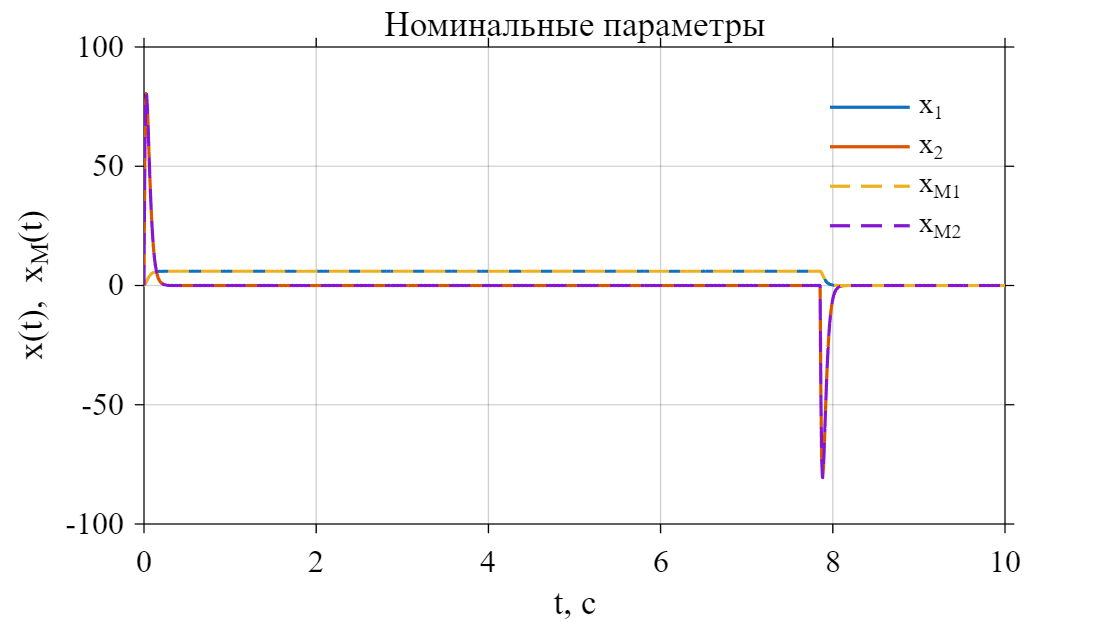

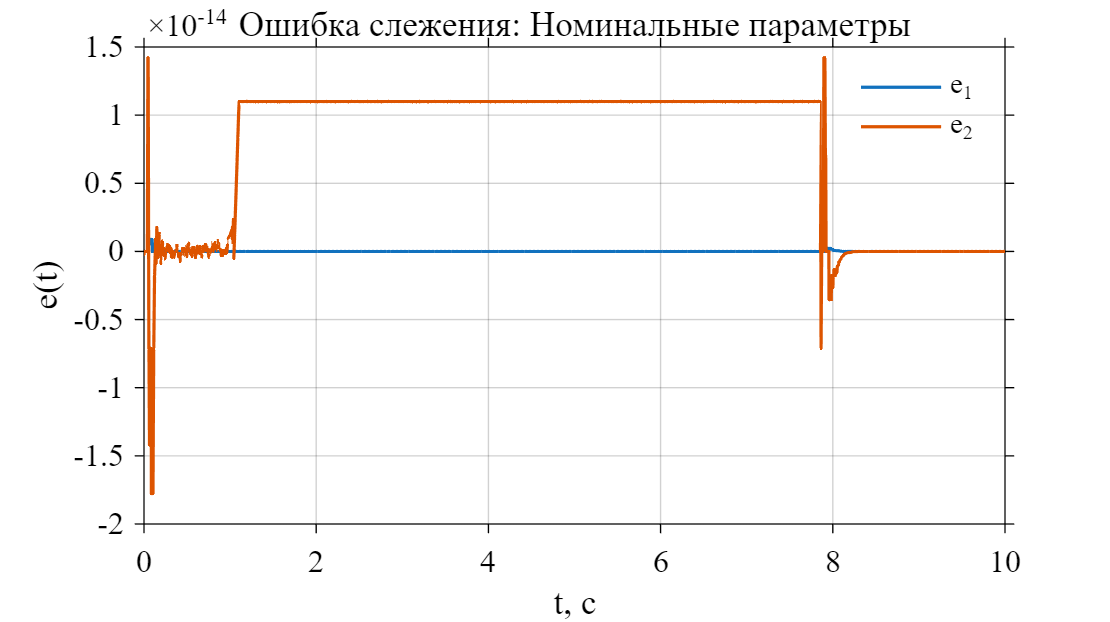

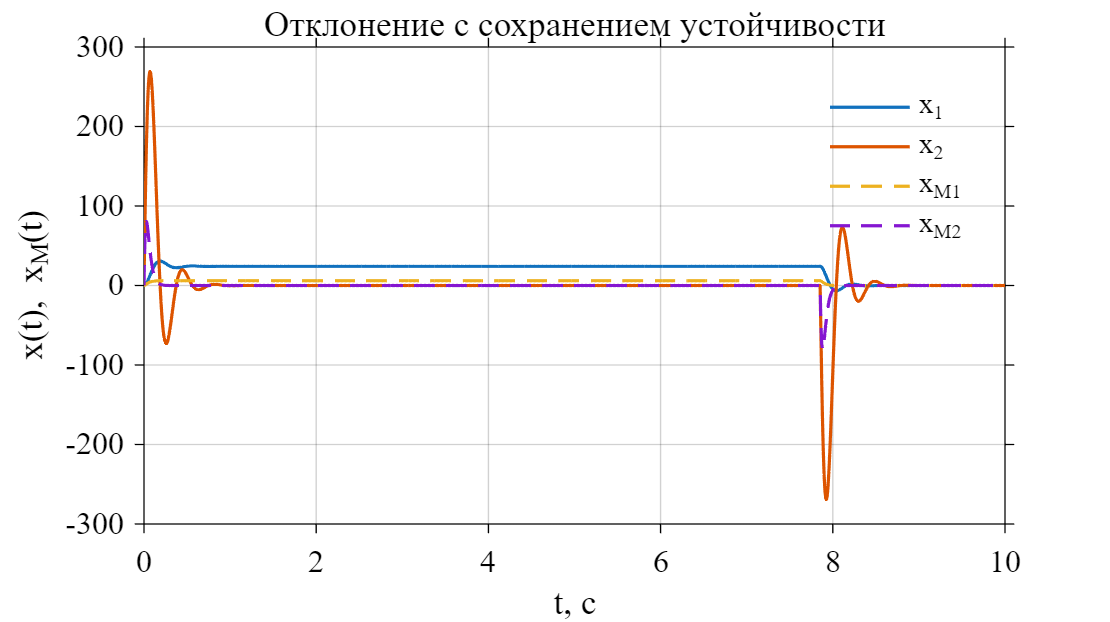

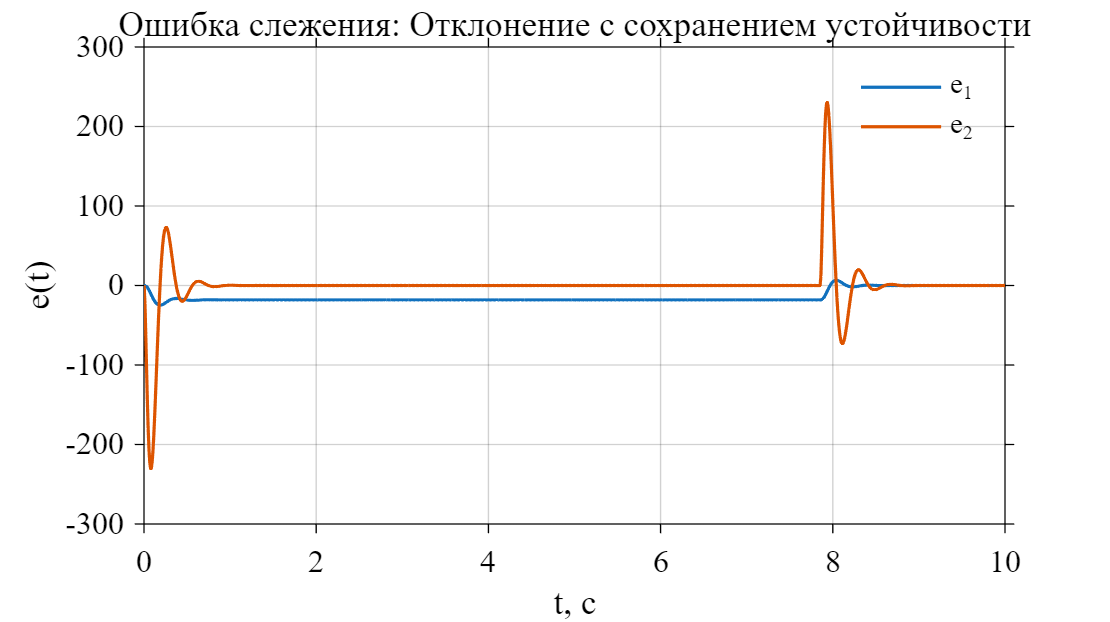

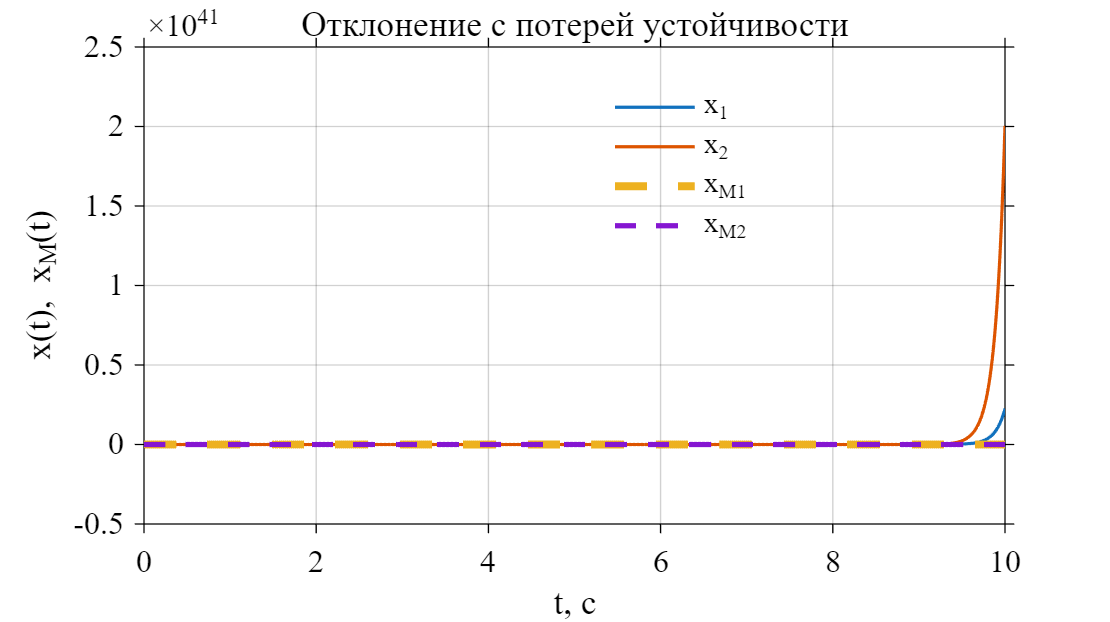

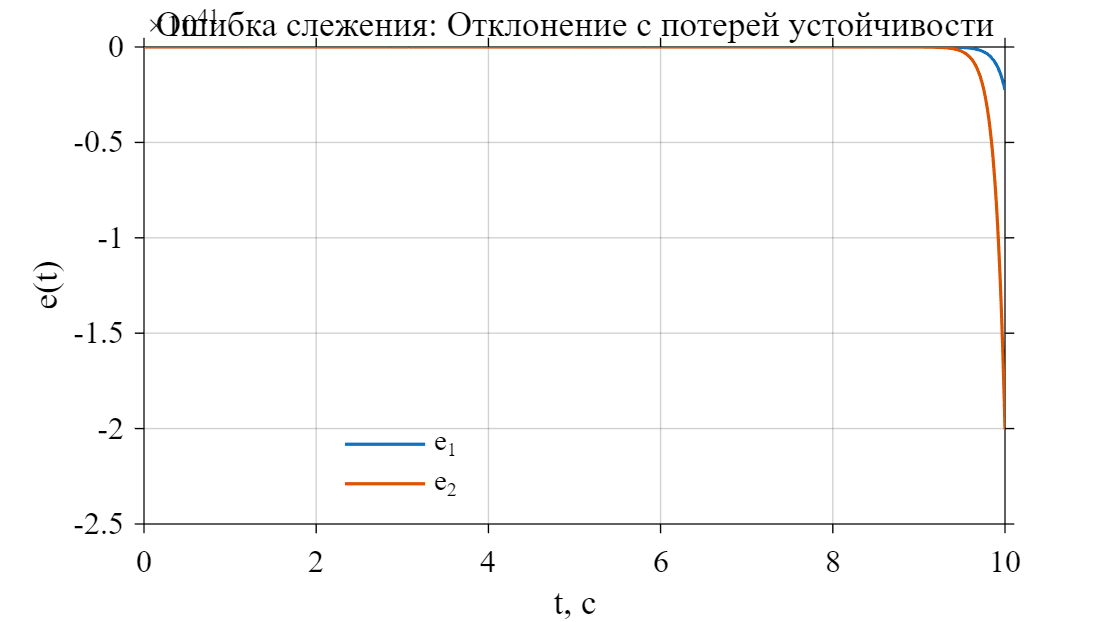

A_M = [0 1; -1329.4782 -72.9240];
b_M = [0; 1329.4782];
b = [0; 1];

a0 = [-1 -1000 -1400];
a1 = [-1 -60 -75];

names = {'nominal', 'stable', 'unstable'};
titles = {'Номинальные параметры', ...
    'Отклонение с сохранением устойчивости', ...
    'Отклонение с потерей устойчивости'};

for k = 1:3
    A = [0 1; -a0(k) -a1(k)];
    out = sim('y2');

    t = out.y.Time;
    x = out.y.Data;
    x_M = out.y_M.Data;
    e = x_M - x;

    codeFolder = fileparts(get_param('y2', 'FileName'));
    fileBase = ['nonadaptive_' names{k}];
    save(fullfile(codeFolder, [fileBase '.mat']), ...
        't', 'x', 'x_M', 'e', 'A');

    fig1 = figure('Color', 'white', 'Position', [100 100 1000 560]);
    ax1 = axes(fig1);
    colororder(ax1, [0 0.35 0.70; 0.85 0.33 0.10; 0.10 0.60 0.30; 0.60 0.20 0.70]);
    plot(ax1, t, x, 'LineWidth', 1.2);
    hold(ax1, 'on');
    ax1.ColorOrderIndex = 3;
    hM = plot(ax1, t, x_M, '--', 'LineWidth', 1.2);
    if k == 3
        hM(1).LineWidth = 3;
        hM(2).LineWidth = 2;
    end
    xlabel(ax1, 't, с', 'Color', 'black');
    ylabel(ax1, 'x(t), x_M(t)', 'Color', 'black');
    title(ax1, titles{k}, 'FontWeight', 'normal', 'Color', 'black');
    legend(ax1, 'x_1', 'x_2', 'x_{M1}', 'x_{M2}', ...
        'Location', 'best', 'Box', 'off', ...
        'TextColor', 'black', 'Color', 'white');

    fig2 = figure('Color', 'white', 'Position', [150 150 1000 560]);
    ax2 = axes(fig2);
    colororder(ax2, [0 0.35 0.70; 0.85 0.33 0.10]);
    plot(ax2, t, e, 'LineWidth', 1.2);
    xlabel(ax2, 't, с', 'Color', 'black');
    ylabel(ax2, 'e(t)', 'Color', 'black');
    title(ax2, ['Ошибка слежения: ' titles{k}], ...
        'FontWeight', 'normal', 'Color', 'black');
    legend(ax2, 'e_1', 'e_2', 'Location', 'best', ...
        'Box', 'off', 'TextColor', 'black', 'Color', 'white');

    set([ax1 ax2], 'Color', 'white', ...
        'FontName', 'Times New Roman', 'FontSize', 12, ...
        'XColor', 'black', 'YColor', 'black', ...
        'XGrid', 'on', 'YGrid', 'on', 'GridAlpha', 0.18, ...
        'Box', 'on', 'TickDir', 'out', 'XLim', [t(1) t(end)]);

    exportgraphics(fig1, ...
        fullfile(codeFolder, '..', 'tex', 'images', [fileBase '.png']), ...
        'Resolution', 300, 'BackgroundColor', 'white');
    exportgraphics(fig2, ...
        fullfile(codeFolder, '..', 'tex', 'images', [fileBase '_error.png']), ...
        'Resolution', 300, 'BackgroundColor', 'white');
end

A_M = [0 1; -1329.4782 -72.9240];
b_M = [0; 1329.4782];
b = [0; 1];
kappa = 1/1329.4782;

p12 = 1/(2*1329.4782);
p22 = (1329.4782 + 1)/(2*1329.4782*72.9240);
p11 = 72.9240*p12 + 1329.4782*p22;
Q = eye(2);
P = [p11 p12; p12 p22];

simTime = 160;
gamma0 = 1000;
codeFolder = pwd;

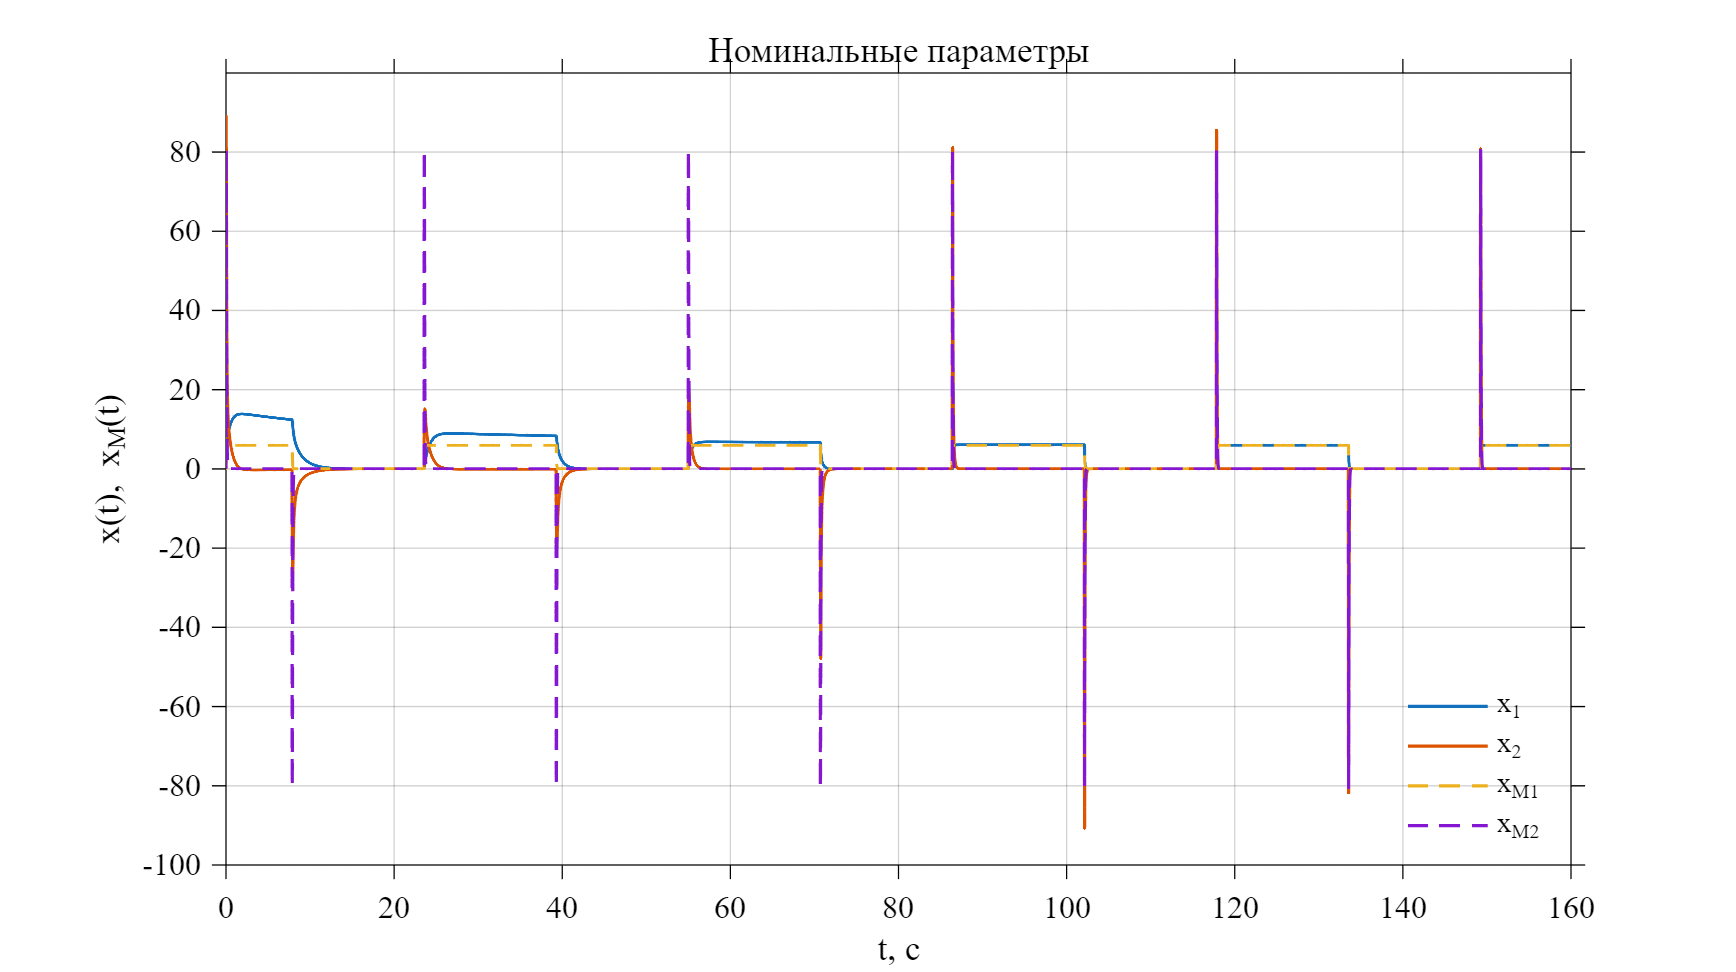

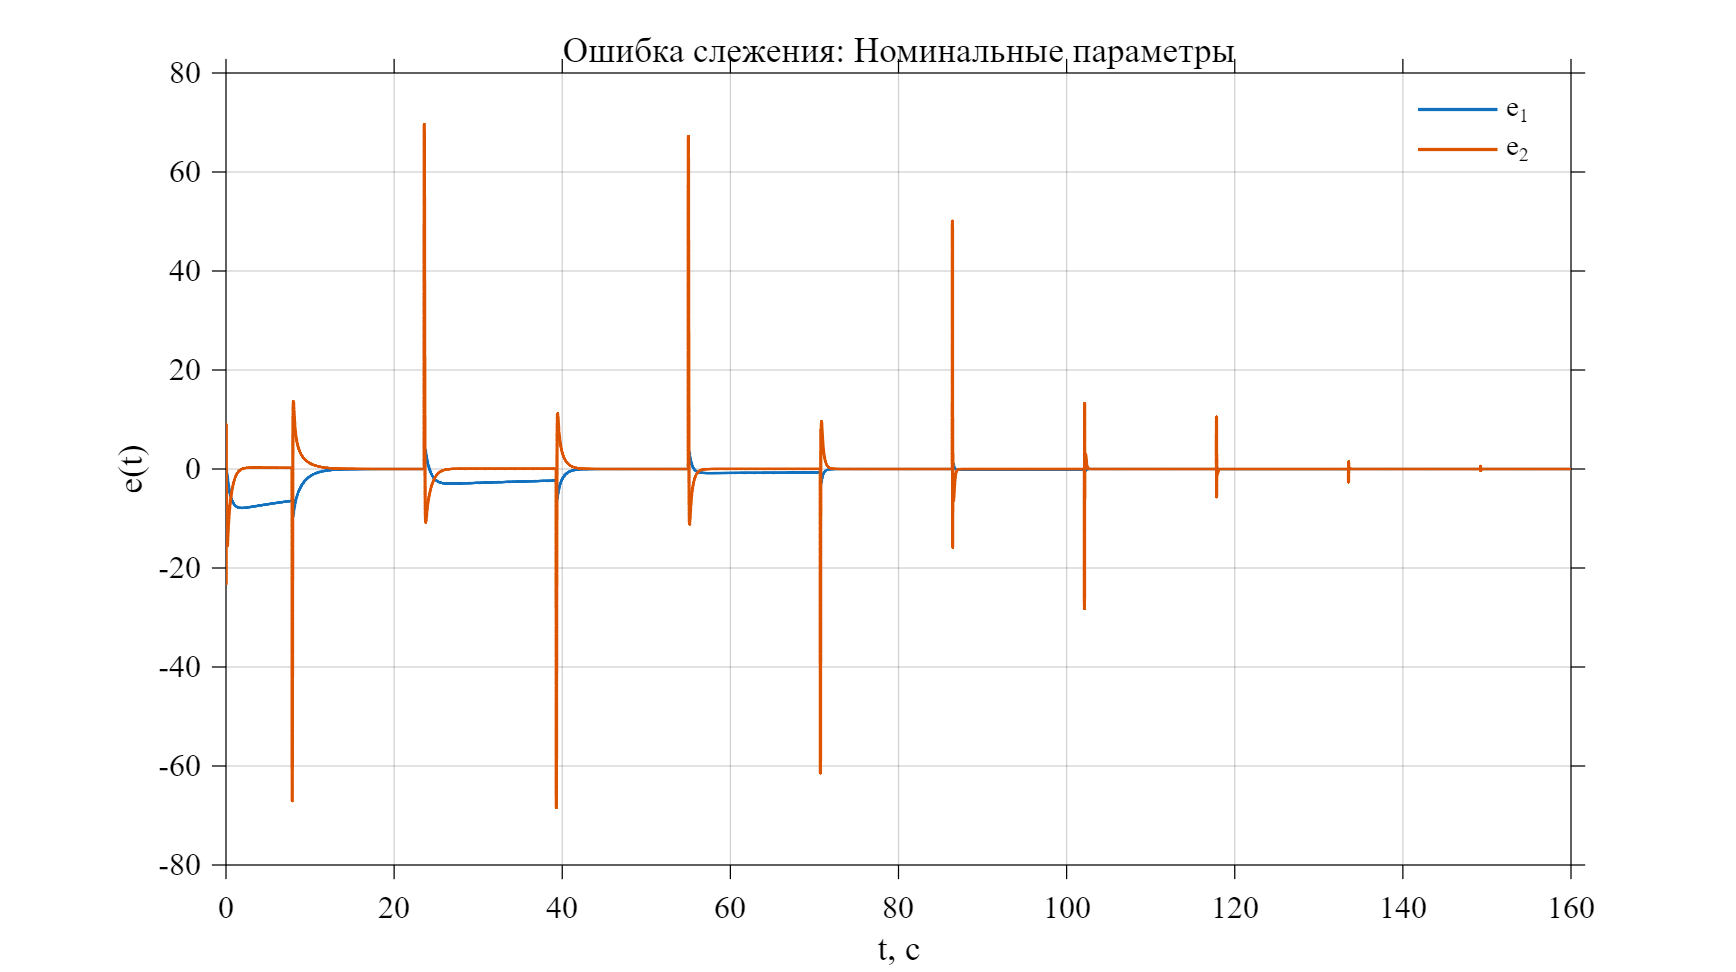

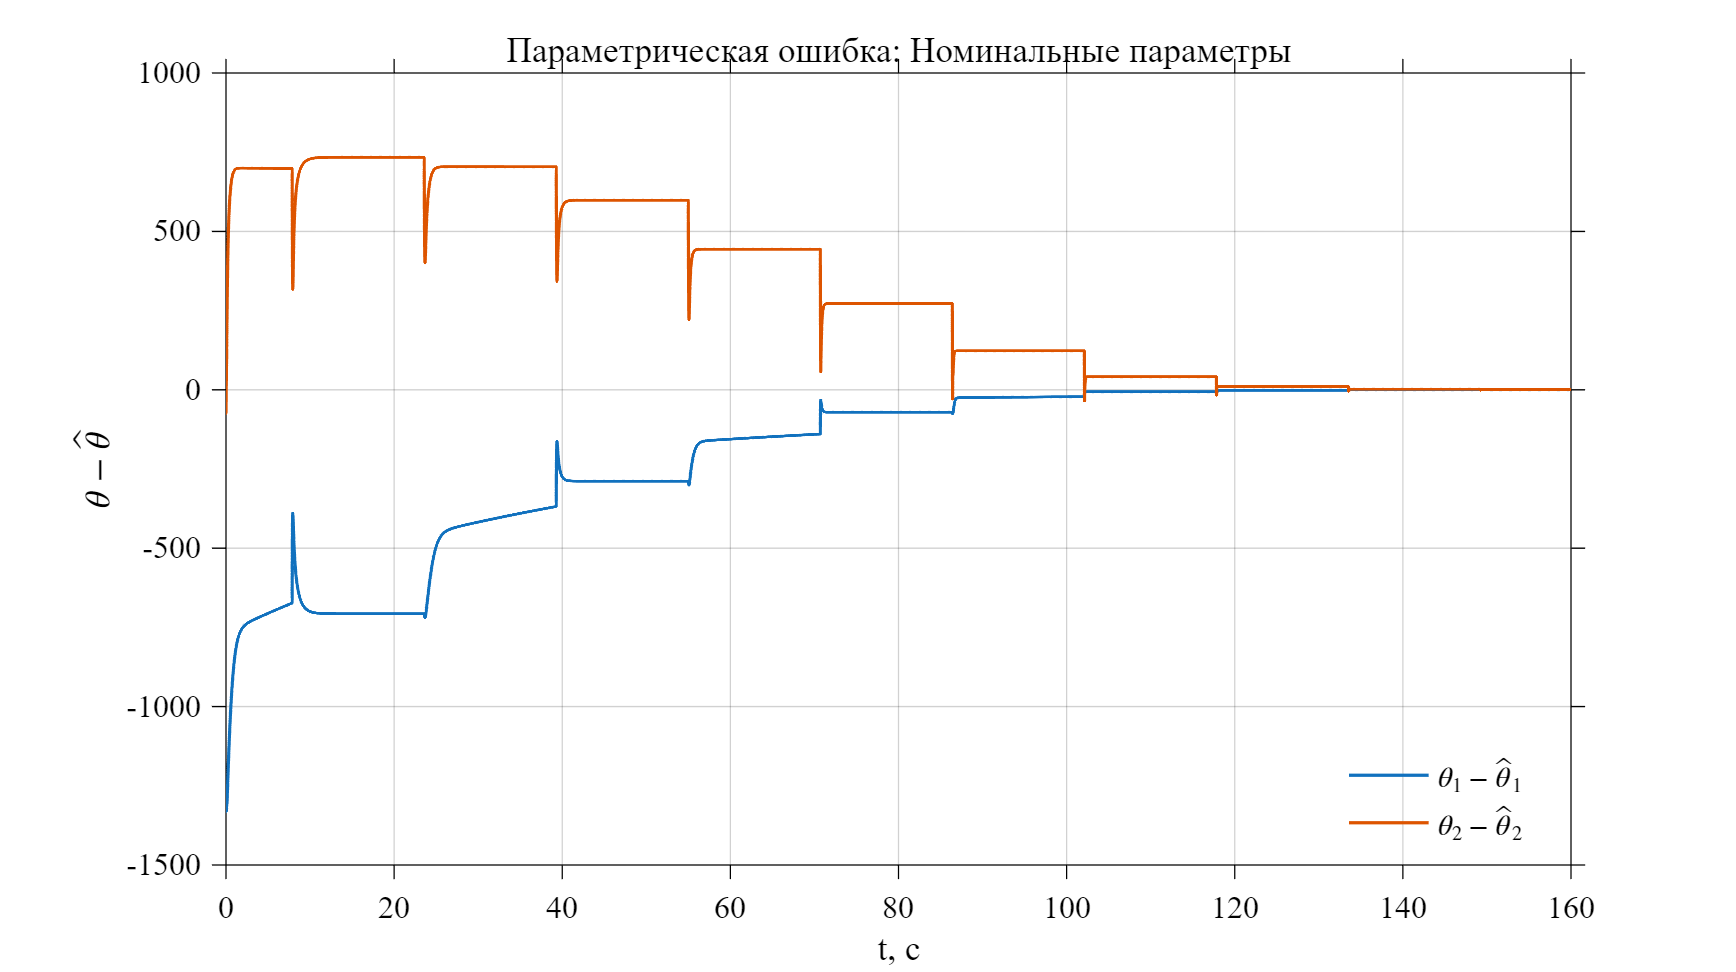

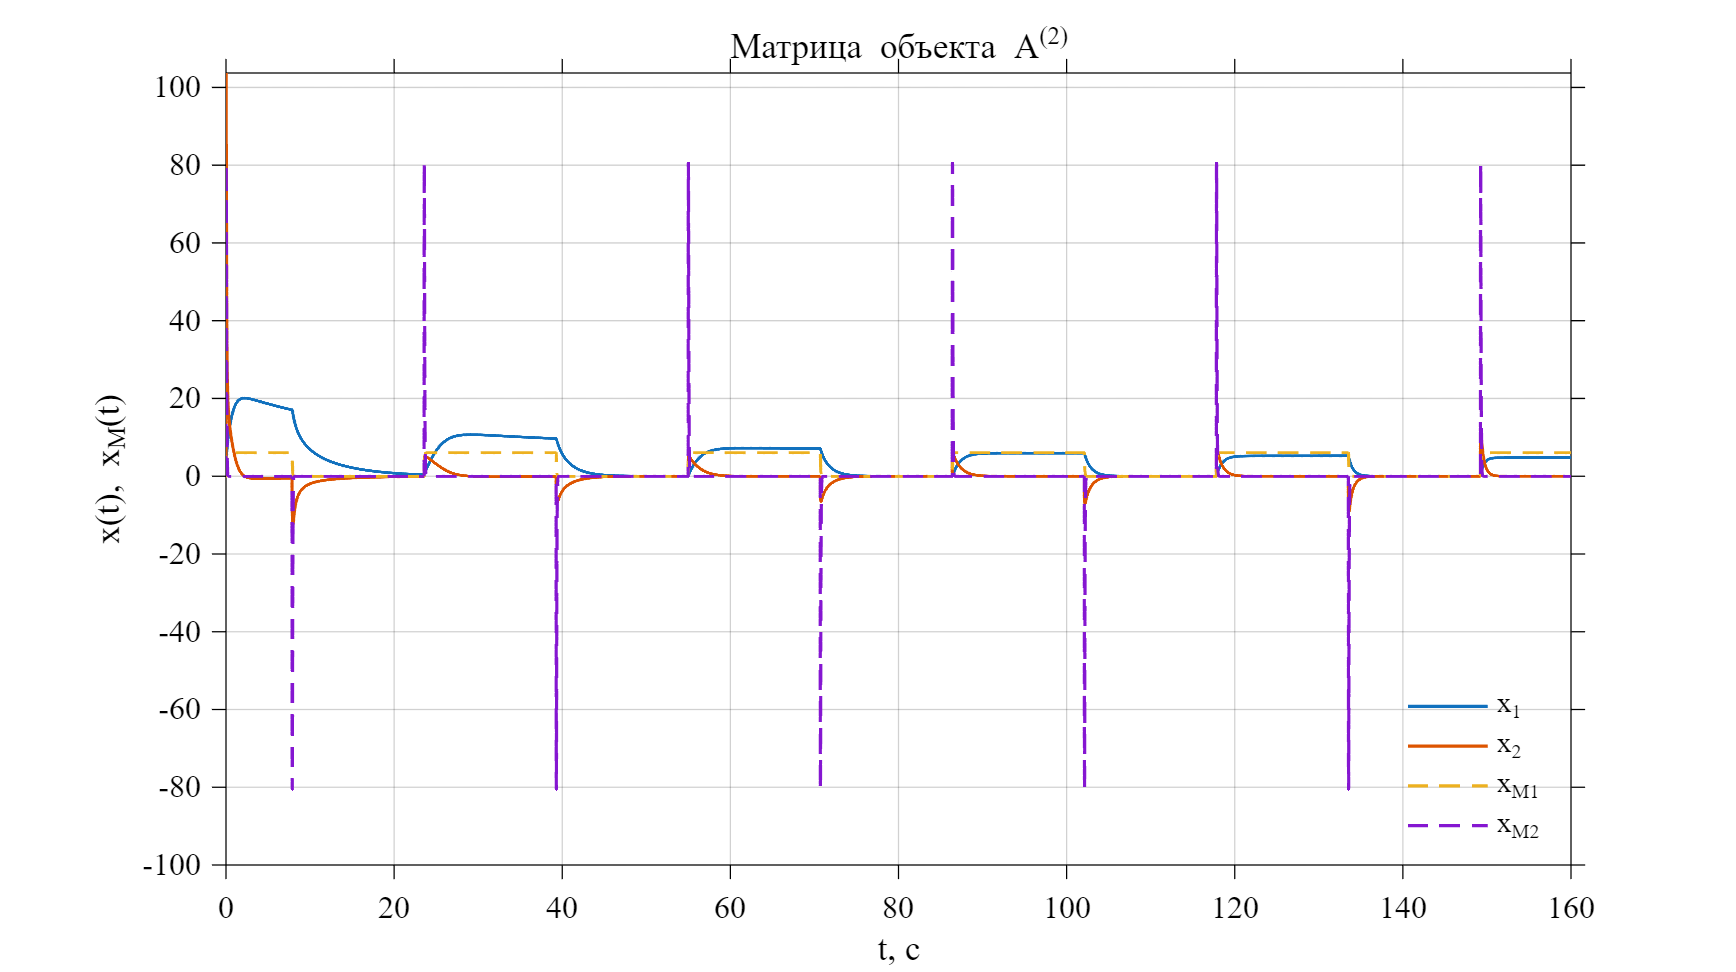

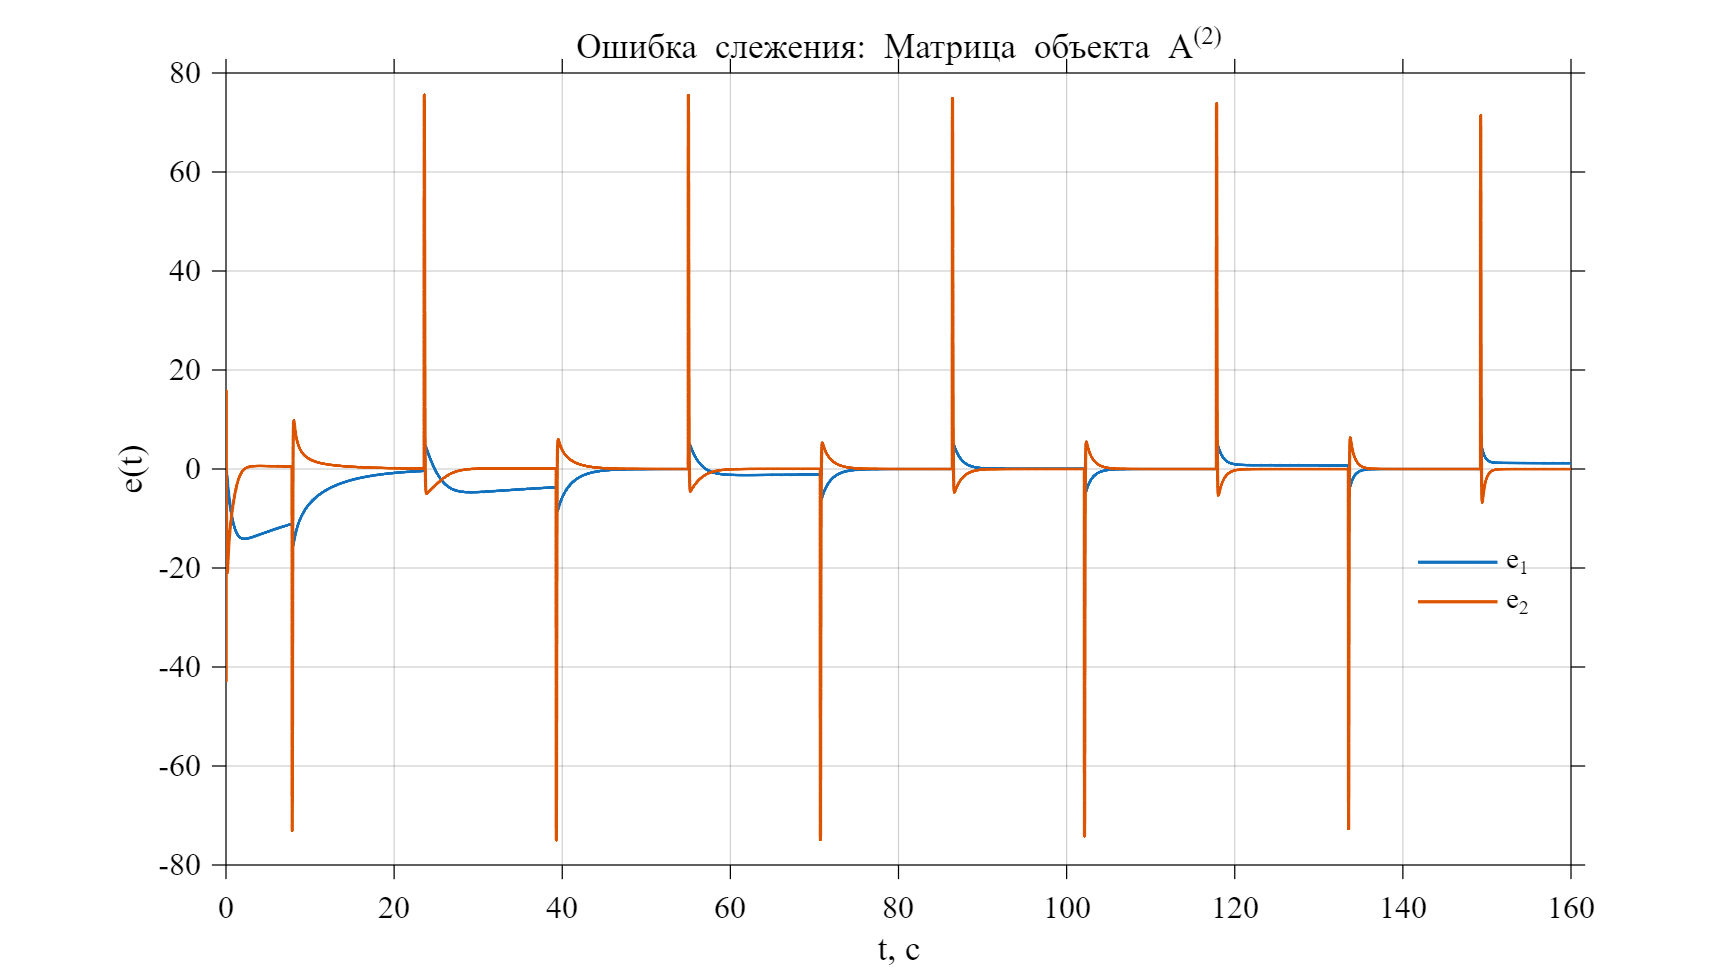

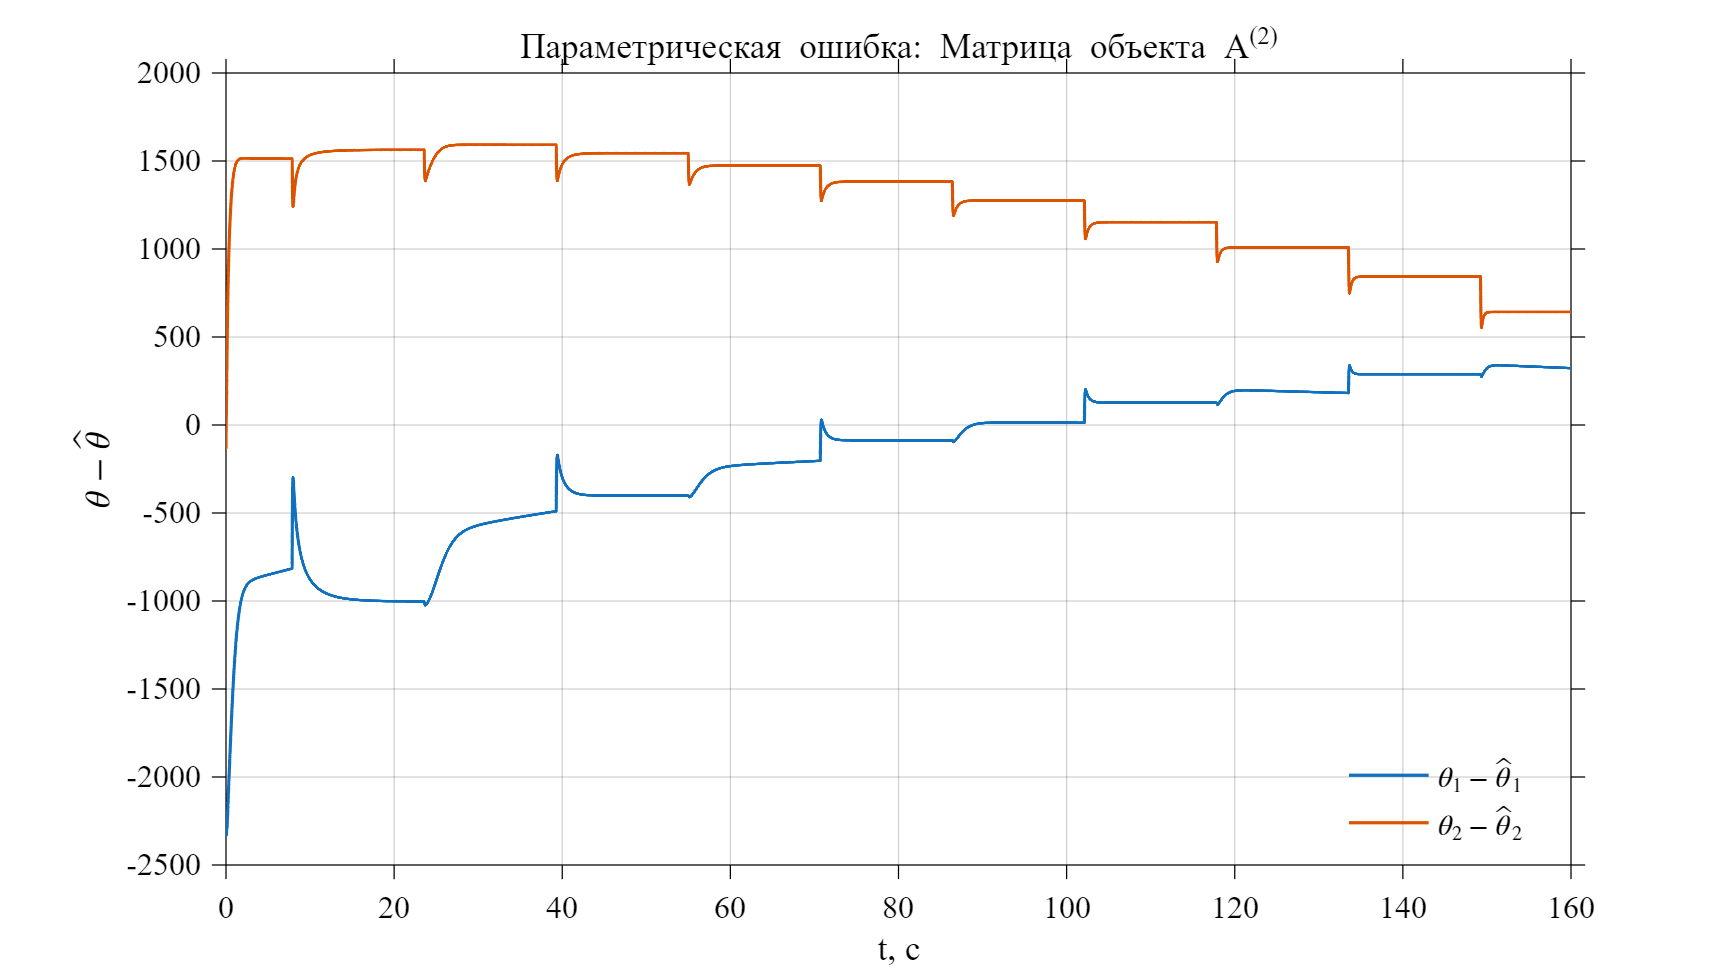

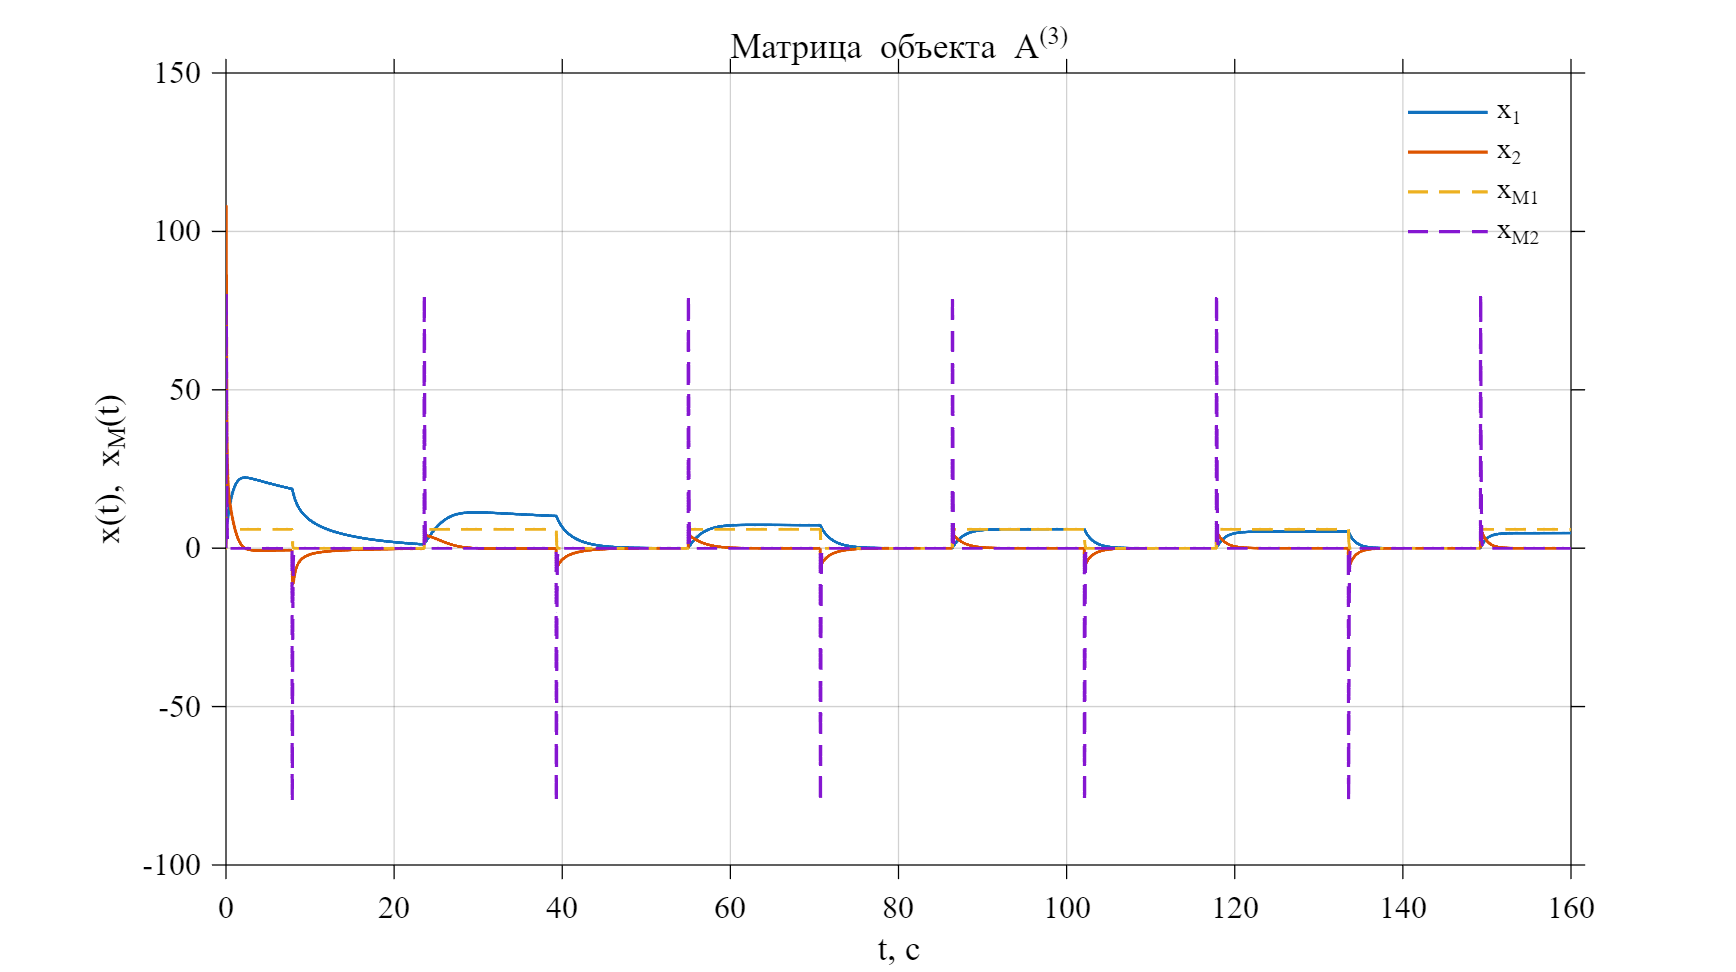

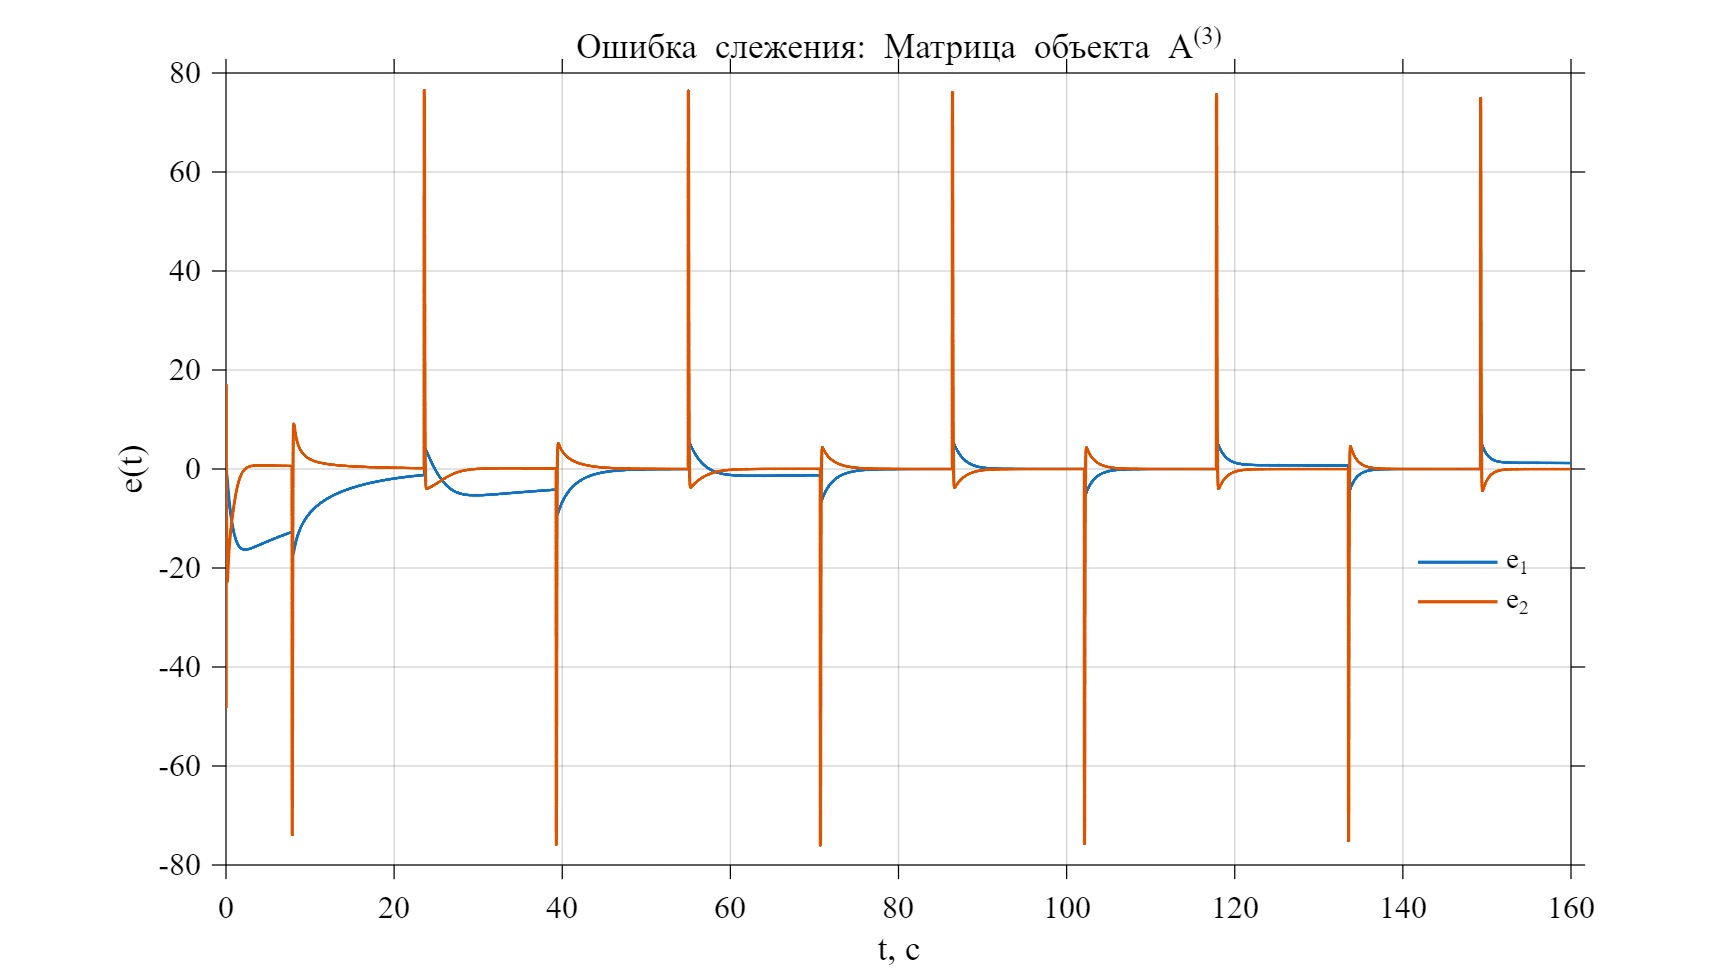

a0 = [-1 -1000 -1400];
a1 = [-1 -60 -75];
names = {'nominal', 'stable', 'unstable'};
titles = {'Номинальные параметры', ...
    'Матрица объекта A^{(2)}', 'Матрица объекта A^{(3)}'};
gamma = gamma0;
g_constant = 0;

for k = 1:3
    A = [0 1; -a0(k) -a1(k)];
    theta = [a0(k) - 1329.4782; a1(k) - 72.9240];
    out = sim(fullfile(codeFolder, 'y3.slx'), ...
        'StopTime', num2str(simTime));
    adaptivePlots(out, theta, A, gamma, g_constant, ...
        ['adaptive_' names{k}], titles{k}, codeFolder);
end

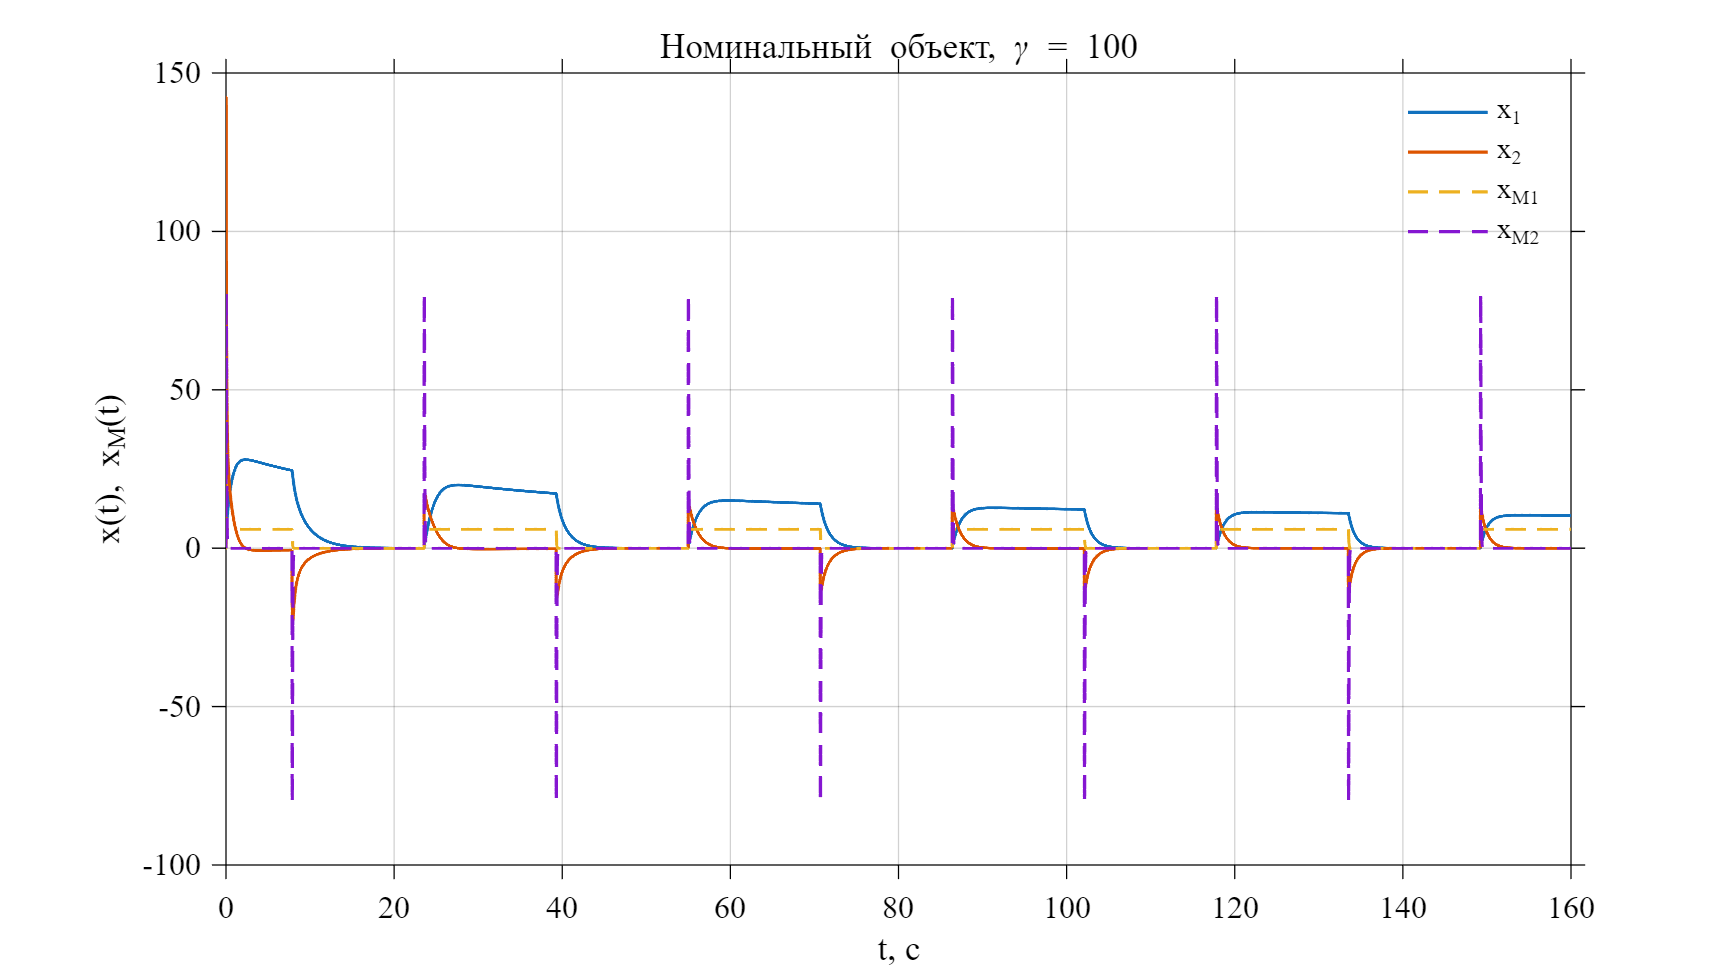

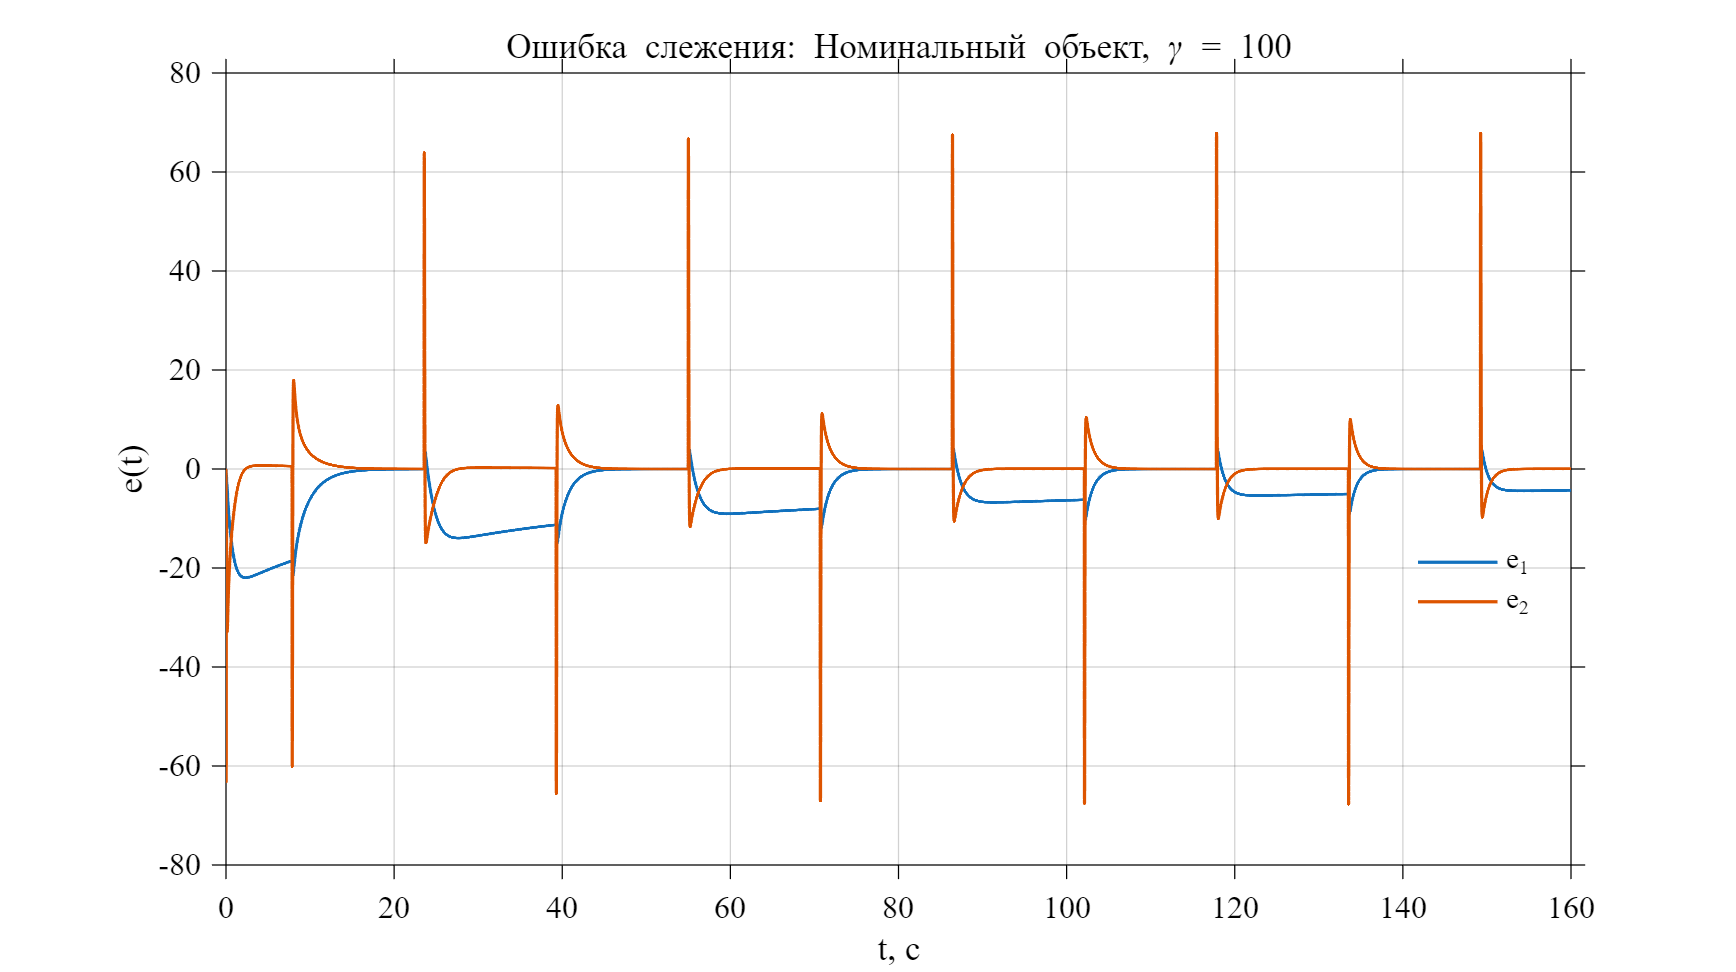

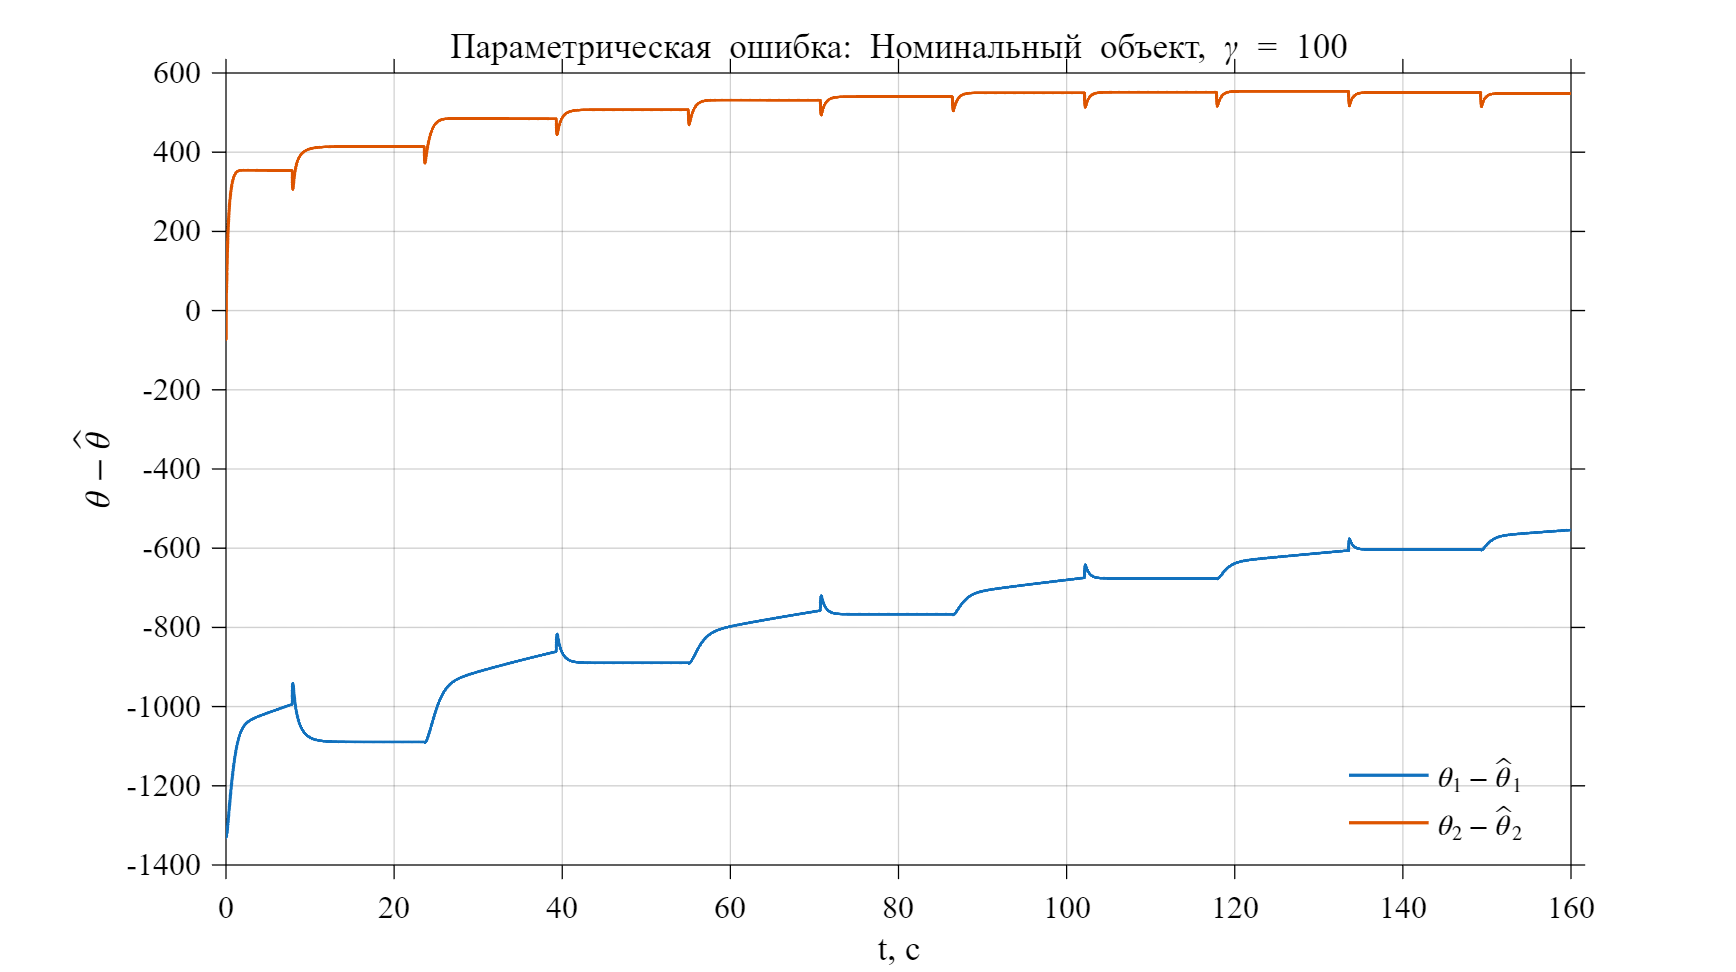

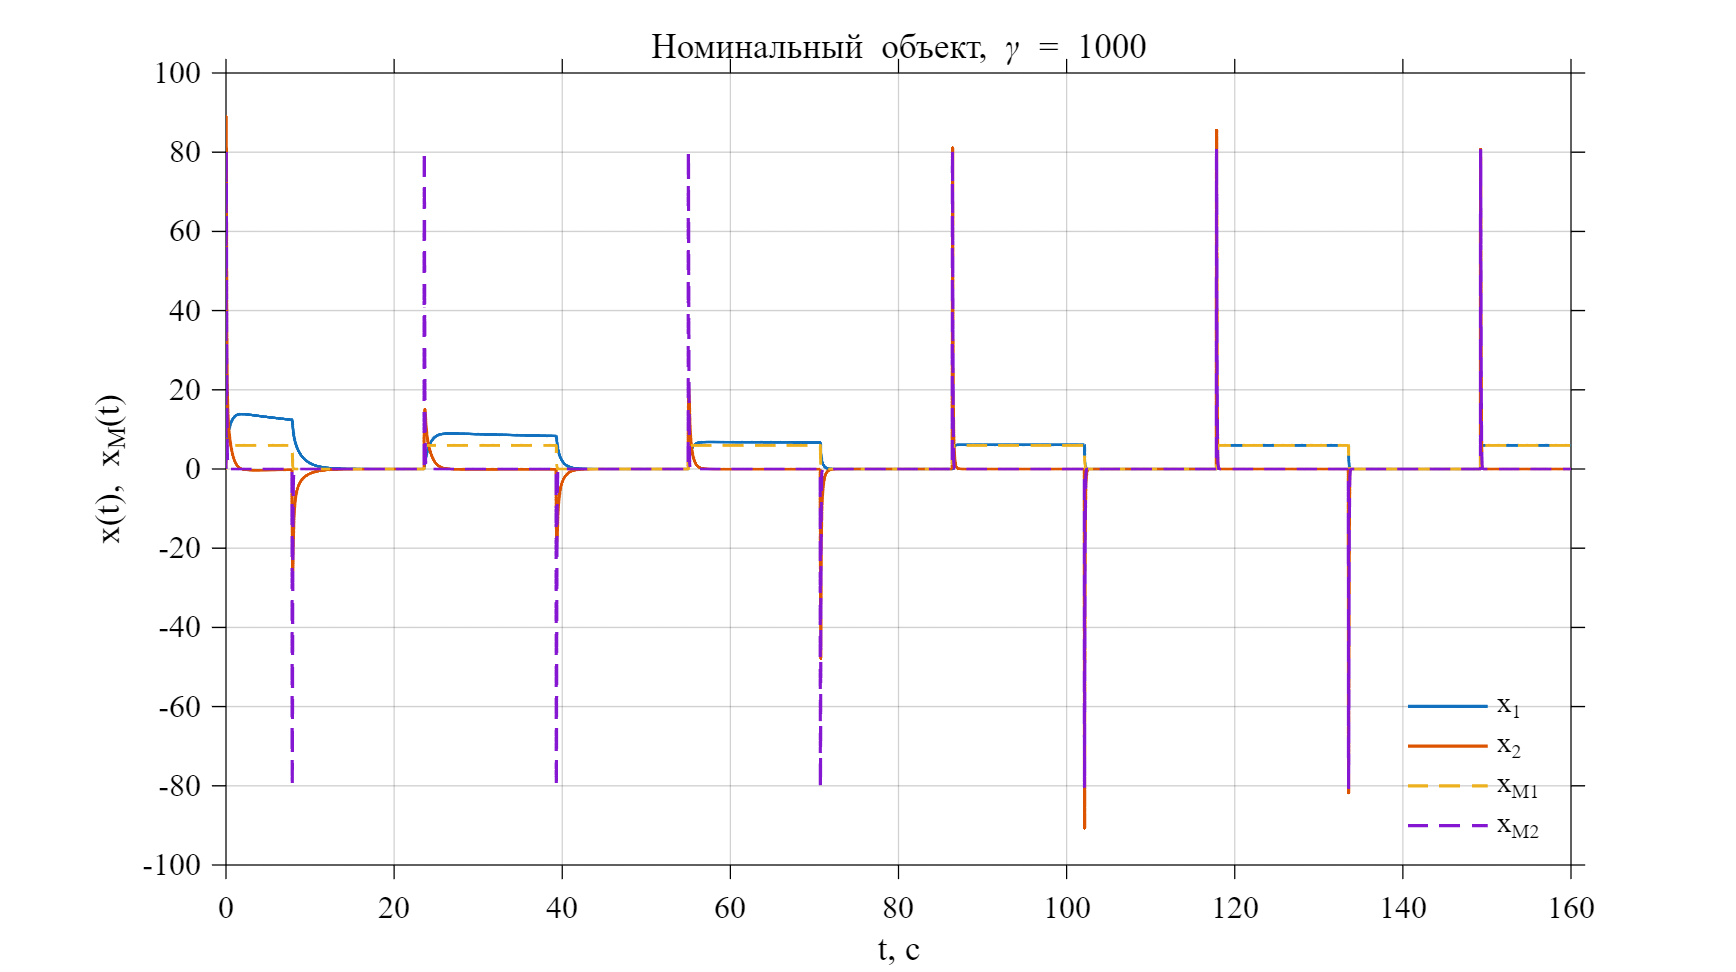

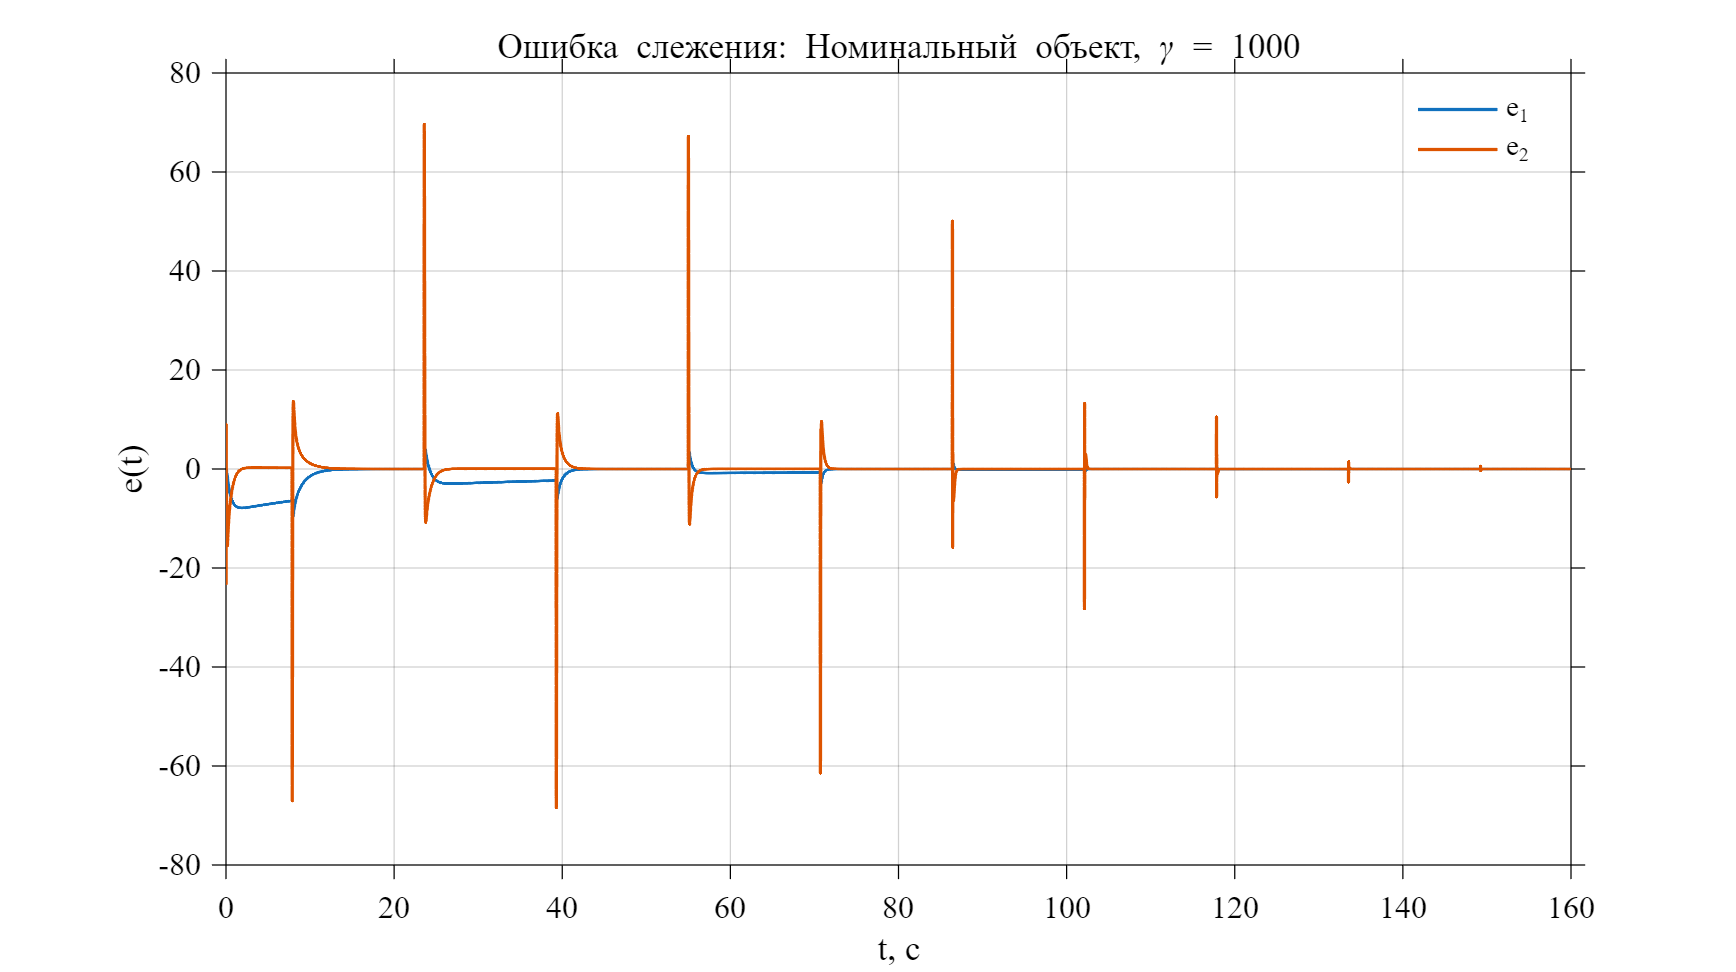

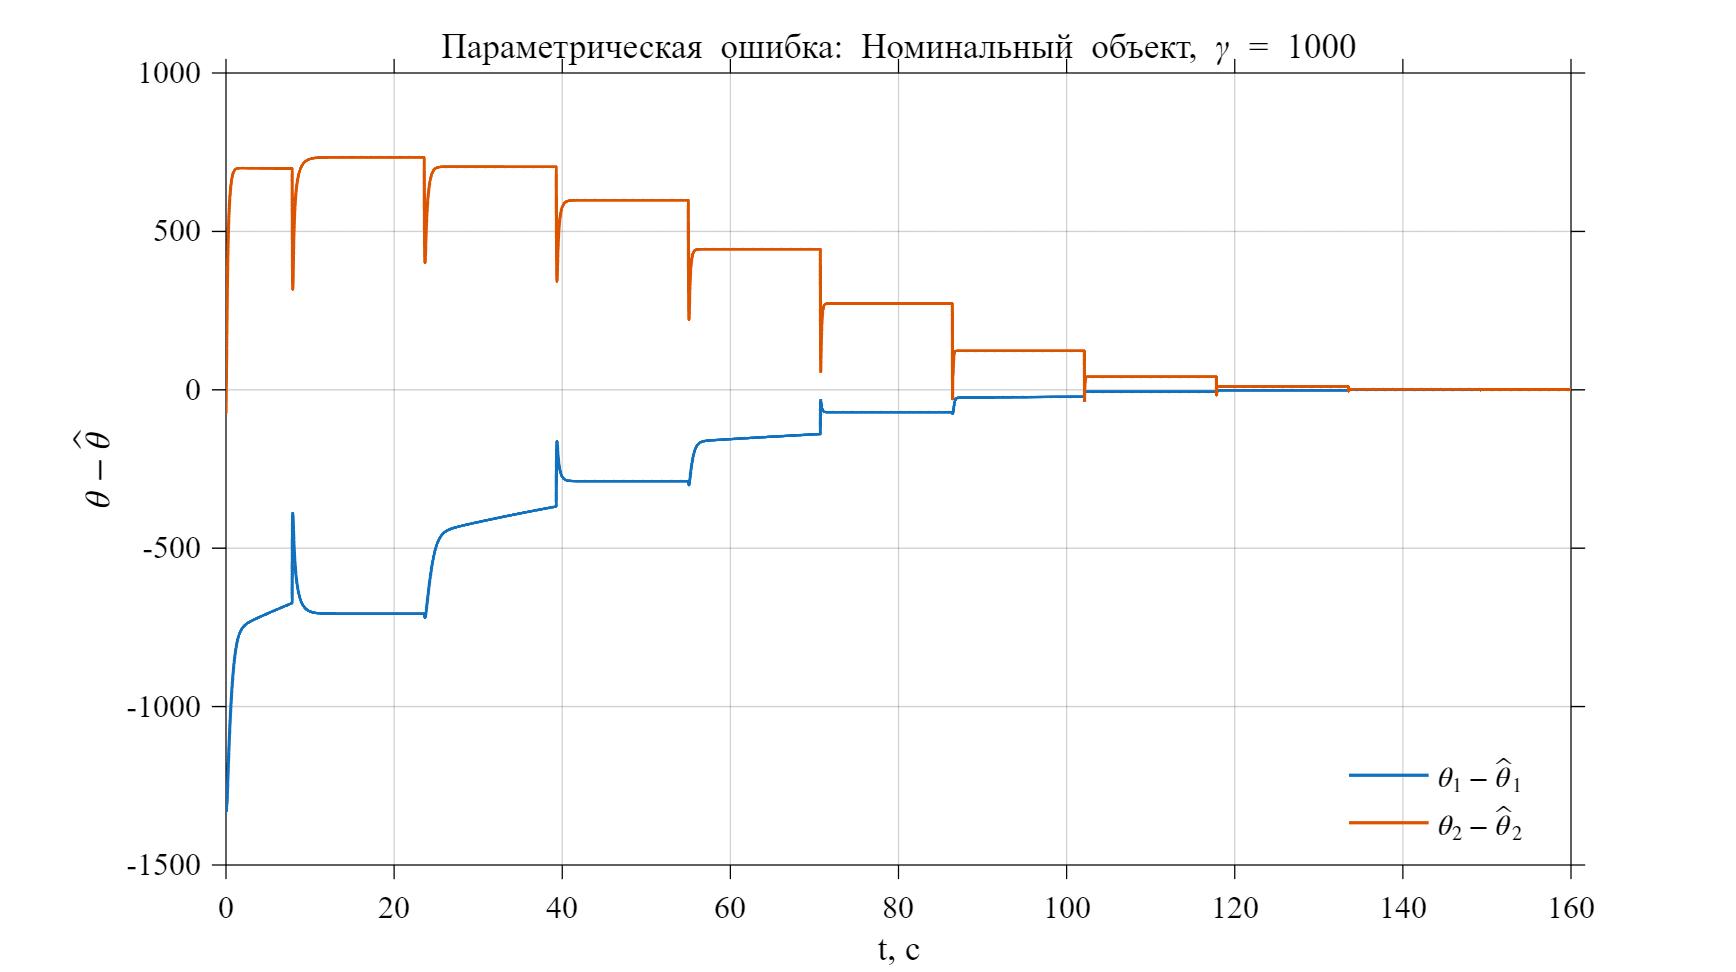

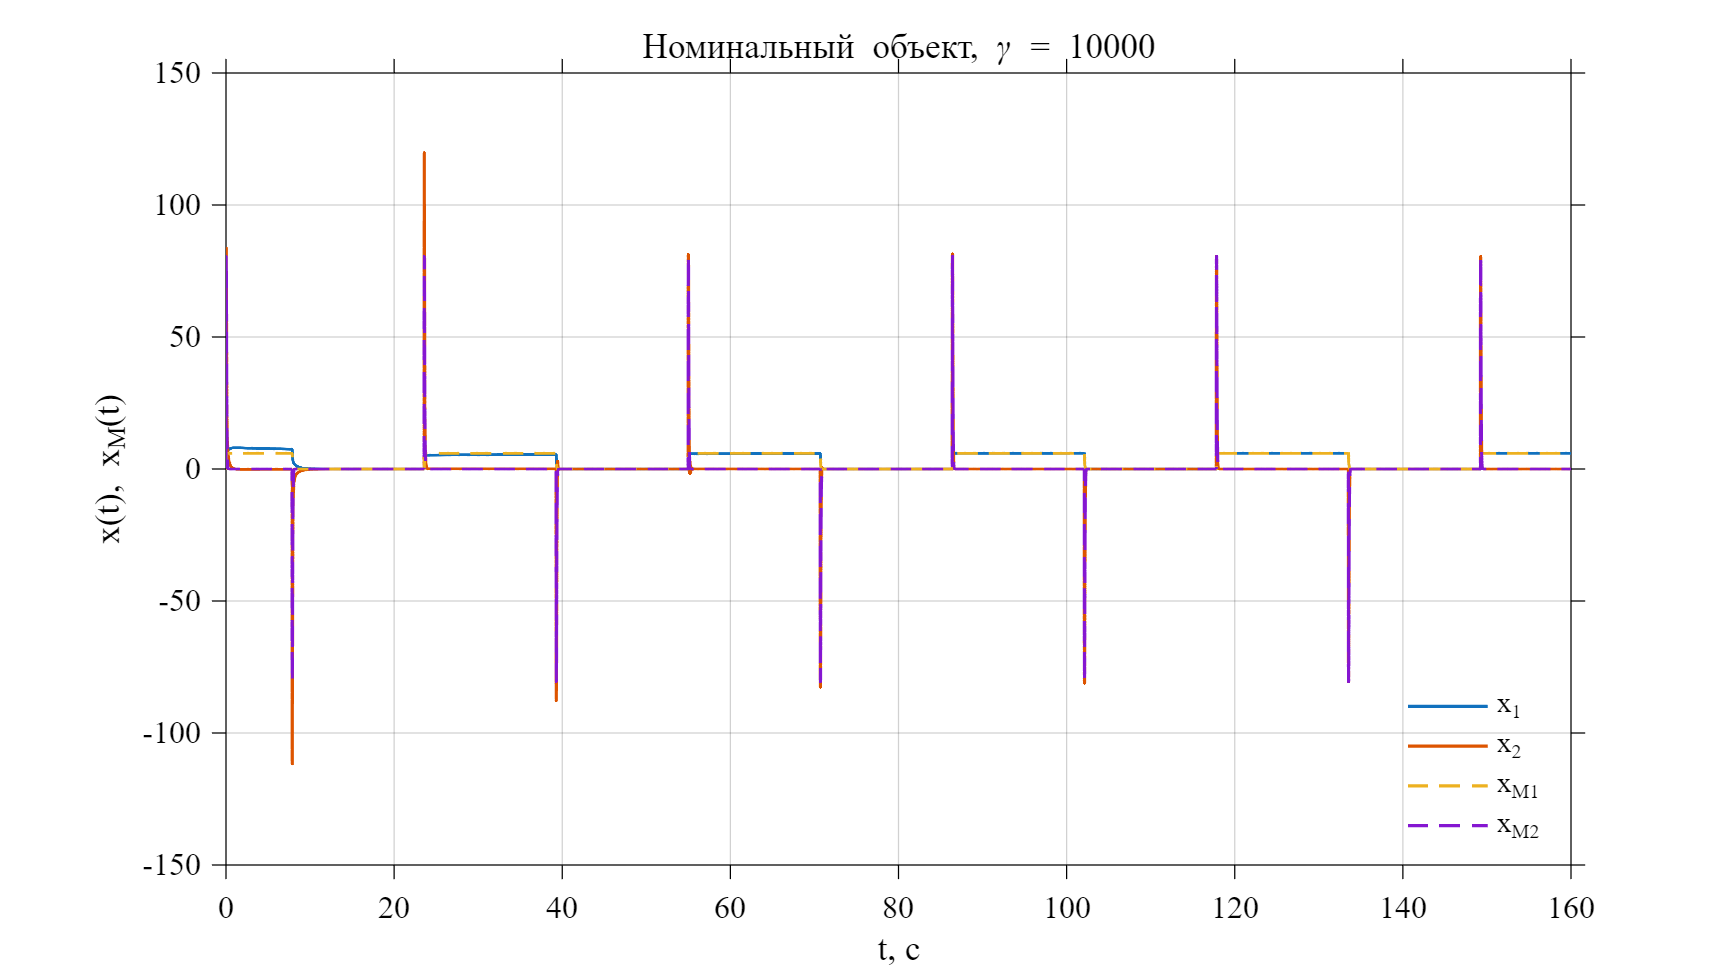

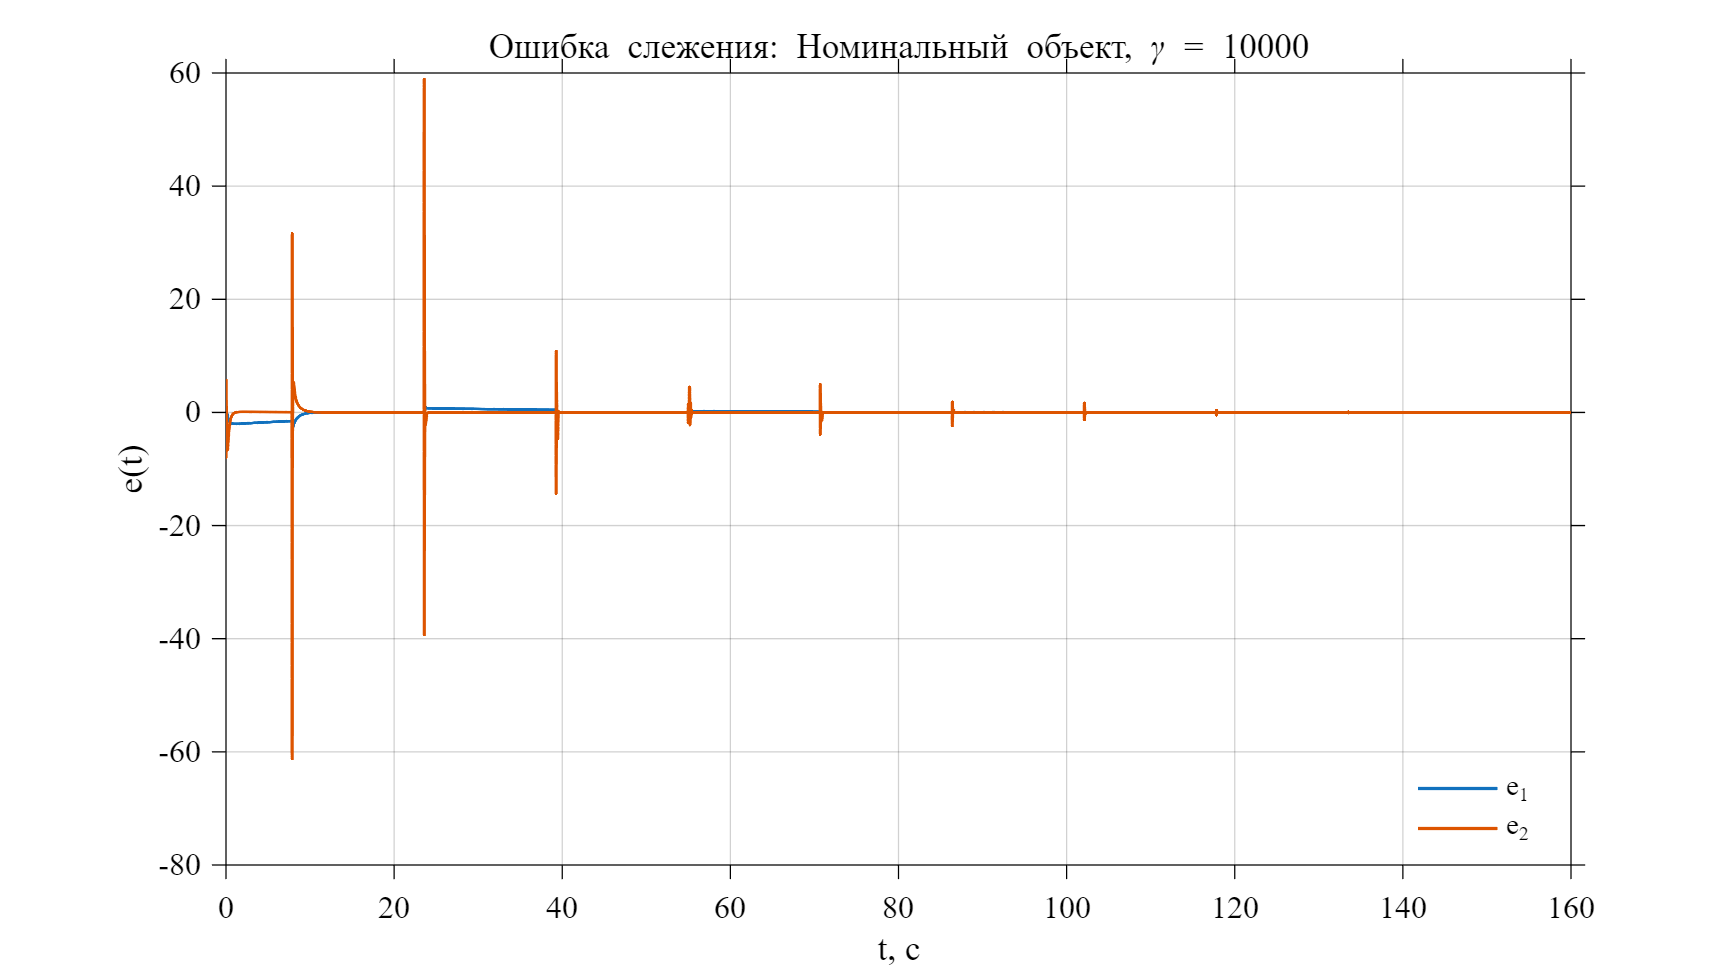

A = [0 1; 1 1];
theta = [-1330.4782; -73.9240];
gammas = [100 1000 10000];
g_constant = 0;

for k = 1:3
    gamma = gammas(k);
    out = sim(fullfile(codeFolder, 'y3.slx'), ...
        'StopTime', num2str(simTime));
    adaptivePlots(out, theta, A, gamma, g_constant, ...
        sprintf('adaptive_gamma_%g', gamma), ...
        sprintf('Номинальный объект, \\gamma = %g', gamma), codeFolder);
end

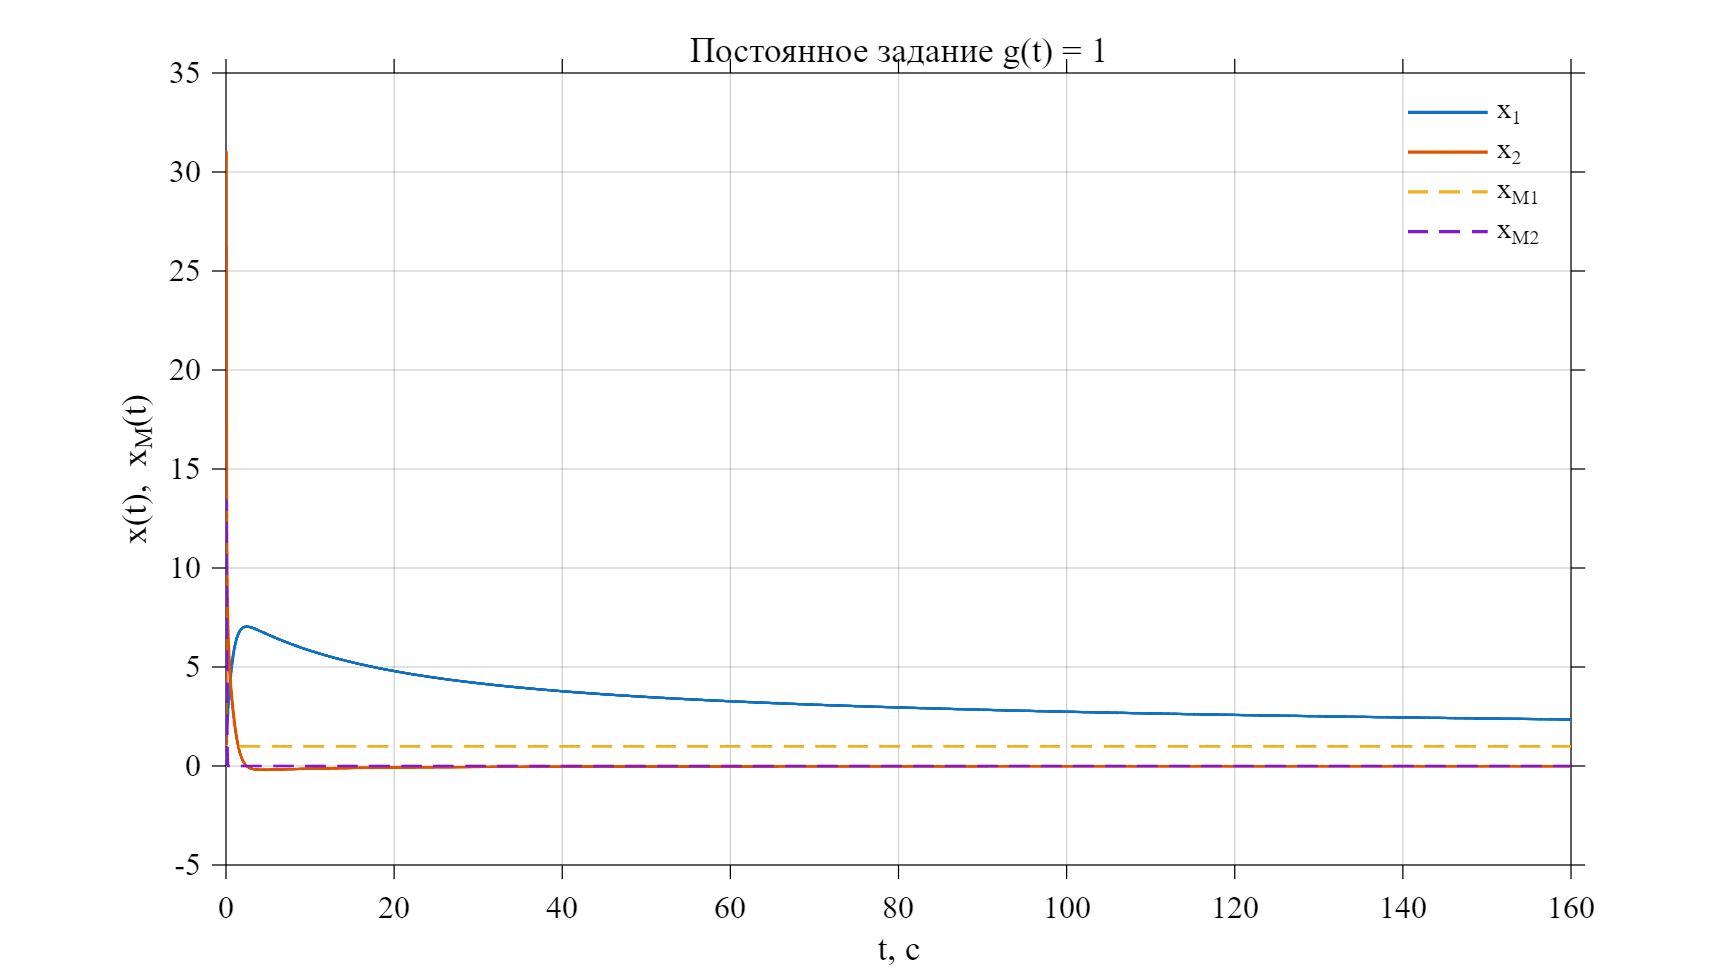

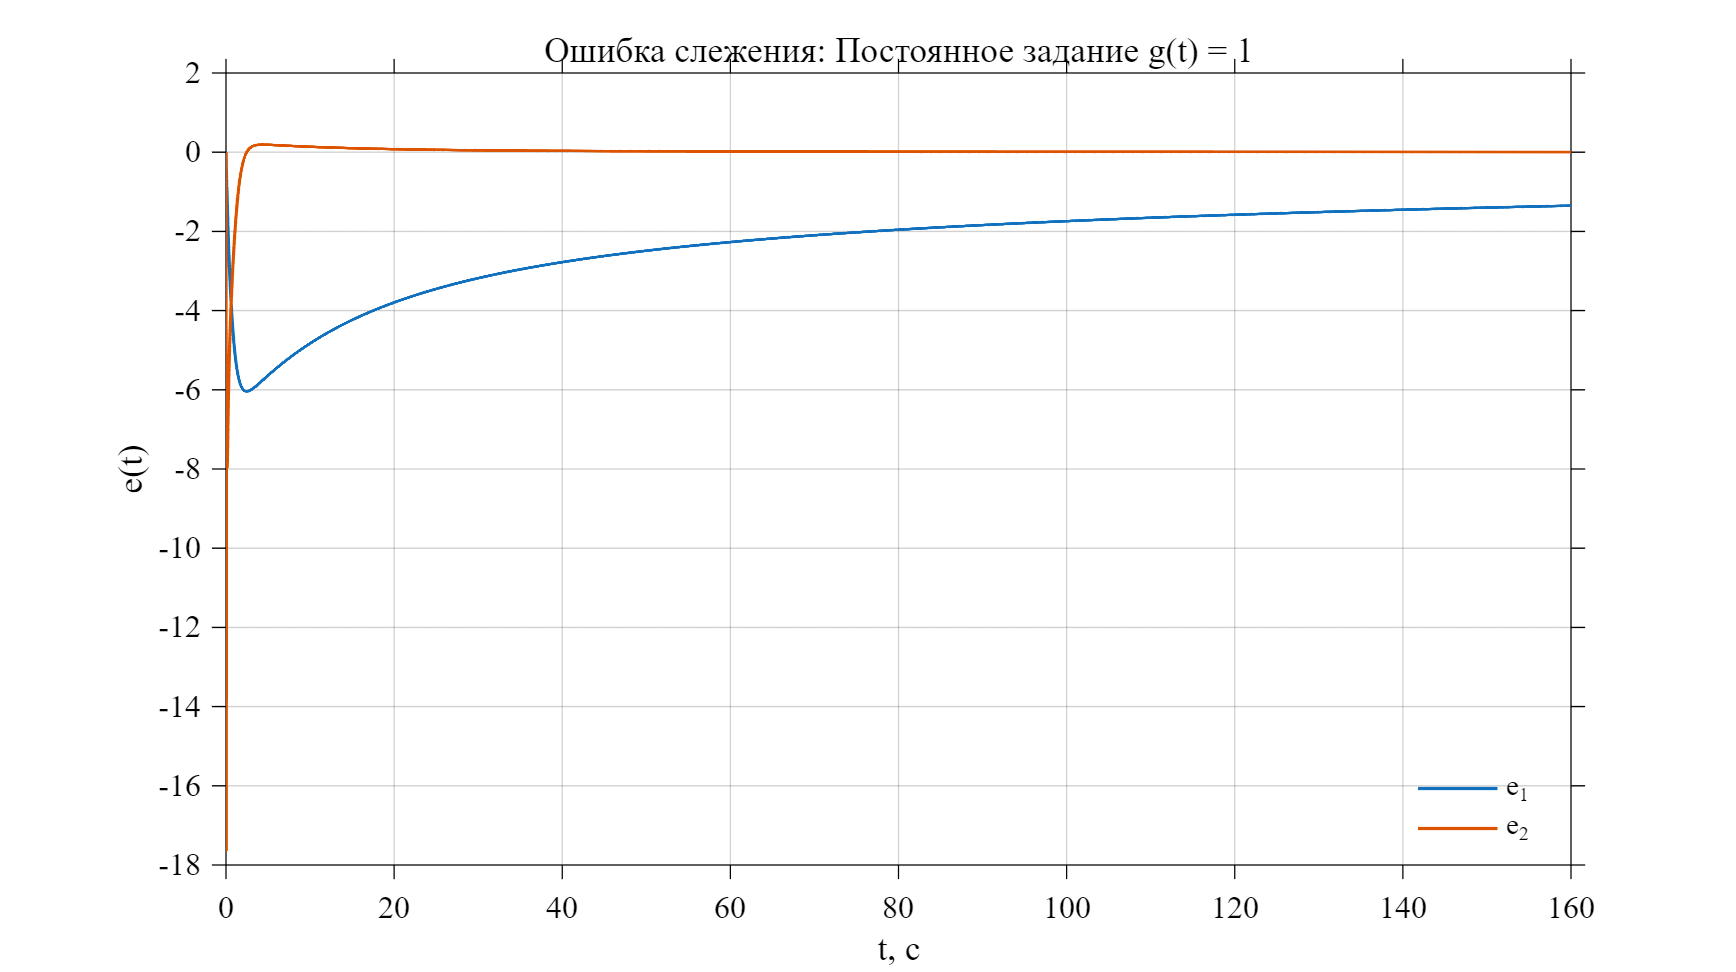

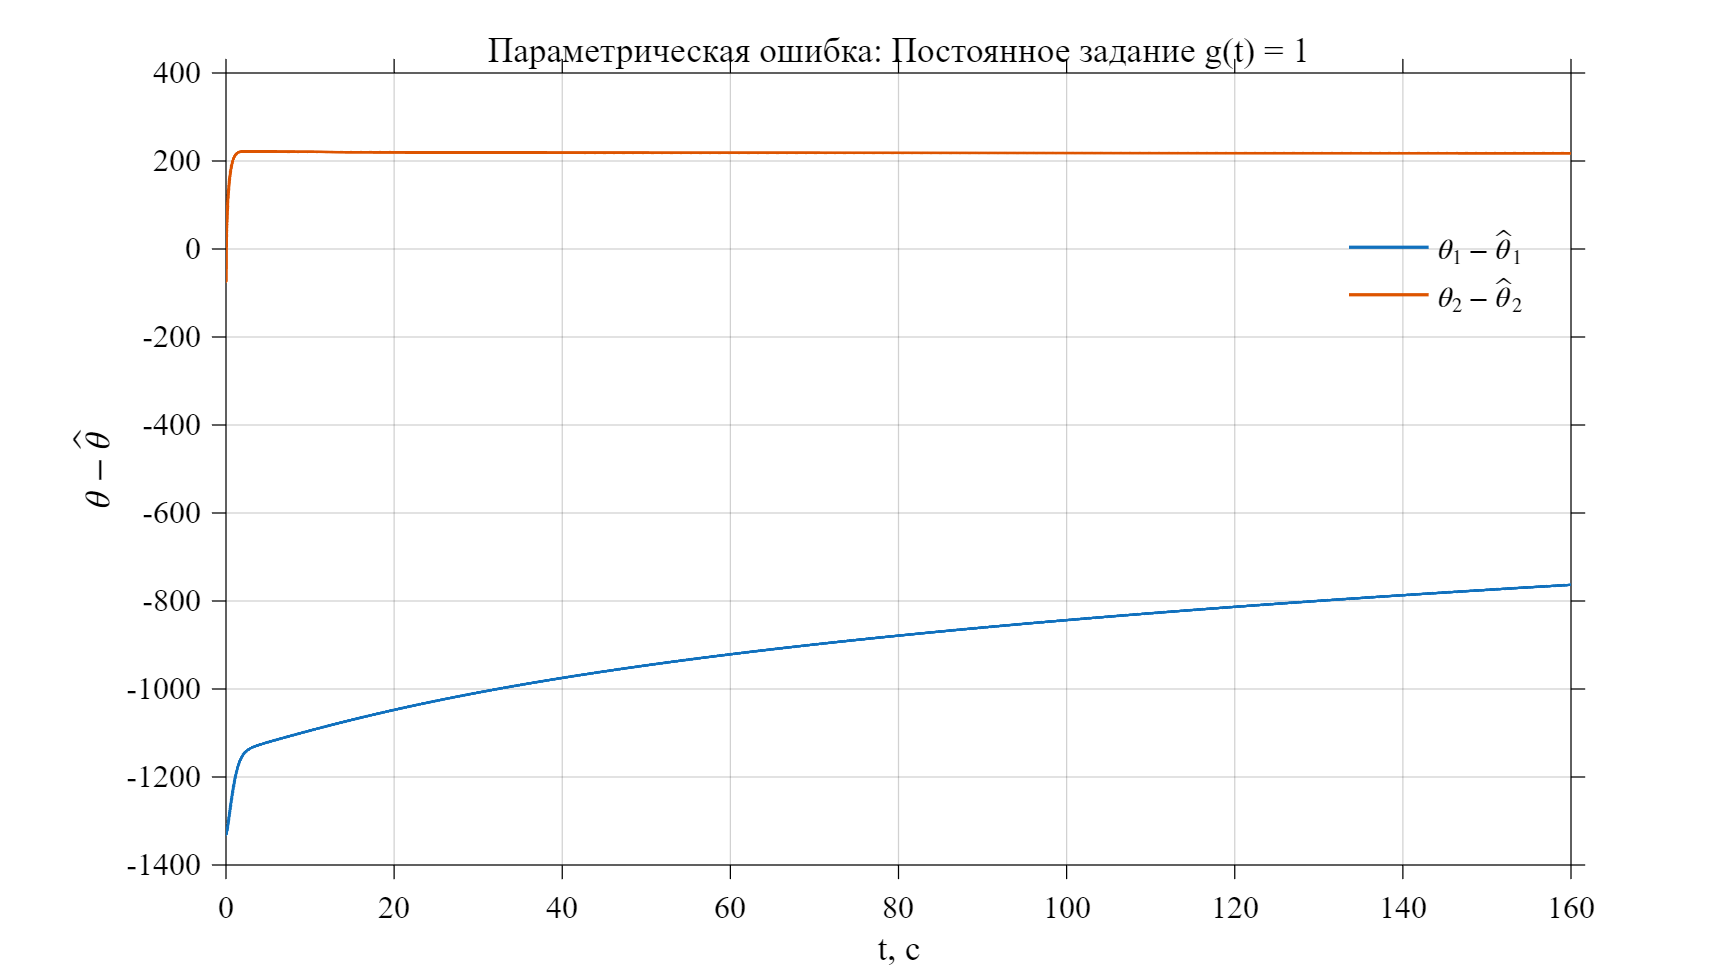

A = [0 1; 1 1];
theta = [-1330.4782; -73.9240];
gamma = gamma0;
g_constant = 1;

out = sim(fullfile(codeFolder, 'y3.slx'), ...
    'StopTime', num2str(simTime));
adaptivePlots(out, theta, A, gamma, g_constant, ...
    'adaptive_constant', 'Постоянное задание g(t) = 1', codeFolder);

function adaptivePlots(out, theta, A, gamma, g_constant, fileBase, plotTitle, codeFolder)
t = out.y.Time;
x = out.y.Data;
x_M = out.y_M.Data;
theta_hat = out.theta_hat.Data;
e = x_M - x;
theta_tilde = theta.' - theta_hat;

save(fullfile(codeFolder, [fileBase '.mat']), ...
    't', 'x', 'x_M', 'e', 'theta_hat', 'theta_tilde', ...
    'theta', 'A', 'gamma', 'g_constant');

fig1 = figure('Color', 'white', 'Position', [100 100 1000 560]);
ax1 = axes(fig1);
colororder(ax1, [0 0.35 0.70; 0.85 0.33 0.10; ...
    0.10 0.60 0.30; 0.60 0.20 0.70]);
plot(ax1, t, x, 'LineWidth', 1.2);
hold(ax1, 'on');
ax1.ColorOrderIndex = 3;
plot(ax1, t, x_M, '--', 'LineWidth', 1.2);
ylabel(ax1, 'x(t), x_M(t)', 'Color', 'black');
title(ax1, plotTitle, 'FontWeight', 'normal', 'Color', 'black');
legend(ax1, 'x_1', 'x_2', 'x_{M1}', 'x_{M2}', ...
    'Location', 'best', 'Box', 'off', ...
    'TextColor', 'black', 'Color', 'white');

fig2 = figure('Color', 'white', 'Position', [150 150 1000 560]);
ax2 = axes(fig2);
colororder(ax2, [0 0.35 0.70; 0.85 0.33 0.10]);
plot(ax2, t, e, 'LineWidth', 1.2);
ylabel(ax2, 'e(t)', 'Color', 'black');
title(ax2, ['Ошибка слежения: ' plotTitle], ...
    'FontWeight', 'normal', 'Color', 'black');
legend(ax2, 'e_1', 'e_2', 'Location', 'best', ...
    'Box', 'off', 'TextColor', 'black', 'Color', 'white');

fig3 = figure('Color', 'white', 'Position', [200 200 1000 560]);
ax3 = axes(fig3);
colororder(ax3, [0 0.35 0.70; 0.85 0.33 0.10]);
plot(ax3, t, theta_tilde, 'LineWidth', 1.2);
ylabel('$\theta-\hat{\theta}$', 'Interpreter', 'latex')
title(ax3, ['Параметрическая ошибка: ' plotTitle], ...
    'FontWeight', 'normal', 'Color', 'black');
legend(ax3, '$\theta_1 - \hat{\theta}_1$', '$\theta_2 - \hat{\theta}_2$', ...
    'Interpreter', 'latex', ...
    'Location', 'best', 'Box', 'off', ...
    'TextColor', 'black', 'Color', 'white');

for ax = [ax1 ax2 ax3]
    xlabel(ax, 't, с', 'Color', 'black');
end
set([ax1 ax2 ax3], 'Color', 'white', ...
    'FontName', 'Times New Roman', 'FontSize', 12, ...
    'XColor', 'black', 'YColor', 'black', ...
    'XGrid', 'on', 'YGrid', 'on', 'GridAlpha', 0.18, ...
    'Box', 'on', 'TickDir', 'out', 'XLim', [t(1) t(end)]);

figures = [fig1 fig2 fig3];
suffixes = {'', '_error', '_theta'};
for j = 1:3
    exportgraphics(figures(j), ...
        fullfile(codeFolder, '..', 'tex', 'images', ...
        [fileBase suffixes{j} '.png']), ...
        'Resolution', 300, 'BackgroundColor', 'white');
end
end